David Nichols

Project 2

12/6/2022

801101888

Part 1

clc;
which myfft.m -all;

C:\Users\alway\Documents\GitHub\DSP\Project 2\myfft.m


which myifft.m -all;

C:\Users\alway\Documents\GitHub\DSP\Project 2\myifft.m


warning off

load('C.mat')
load('Ell.mat')
load('Least.mat')
load('butter.mat')
load('B_Rect.mat')
load('B_Hann.mat')

%setup for N and x_n
N = 6;
n = 0:1:N-1;
x_n = transpose(cos((pi/3).*n));

%find fourier transform
X_k = myfft(x_n)

X_k =   -0.0000 + 0.0000i
   3.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   3.0000 - 0.0000i


X_K_Checking = fft(x_n)

X_K_Checking =   -0.0000 + 0.0000i
   3.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   3.0000 + 0.0000i


X_k_ifft = myifft(X_k)

X_k_ifft =    6.0000 - 0.0000i
   3.0000 - 0.0000i
  -3.0000 + 0.0000i
  -6.0000 + 0.0000i
  -3.0000 + 0.0000i
   3.0000 - 0.0000i


error = sum(real(x_n - X_k_ifft)) %e-15 error need to check if thats acceptable

error = 8.8818e-15

As you can see from above, the myfft.m file works due to having the same values as the built in function.

Task 2

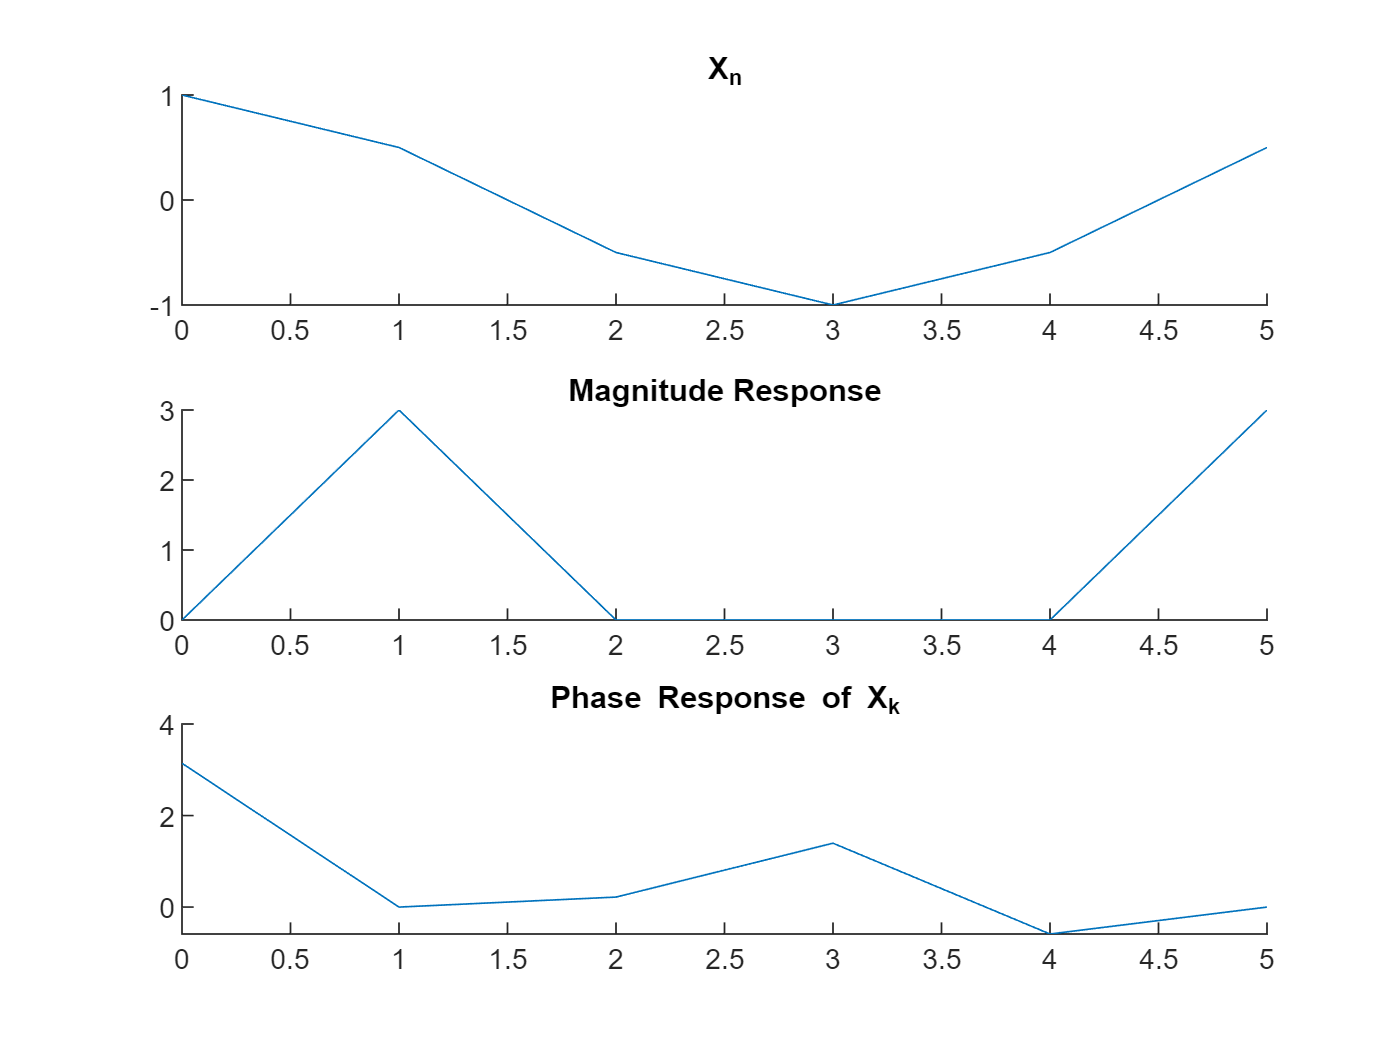

figure(1)
subplot(3,1,1)
hold on
plot(n,x_n)
title("X_n")

subplot(3,1,2);
hold on
title('Magnitude Response');
plot(n,abs(X_k));

subplot(3,1,3);
hold on
title('Phase Response of X_k')
plot(n,angle(X_k));

Task 3

(15pts) Explain the following: For each index k, explain the (possibly complex) observed value of the DFT, X[k], in terms of the magnitude and phase of the complex number (there are 5 such numbers)

Answer: At every index K  we can see the complex and real parts 

Task 4

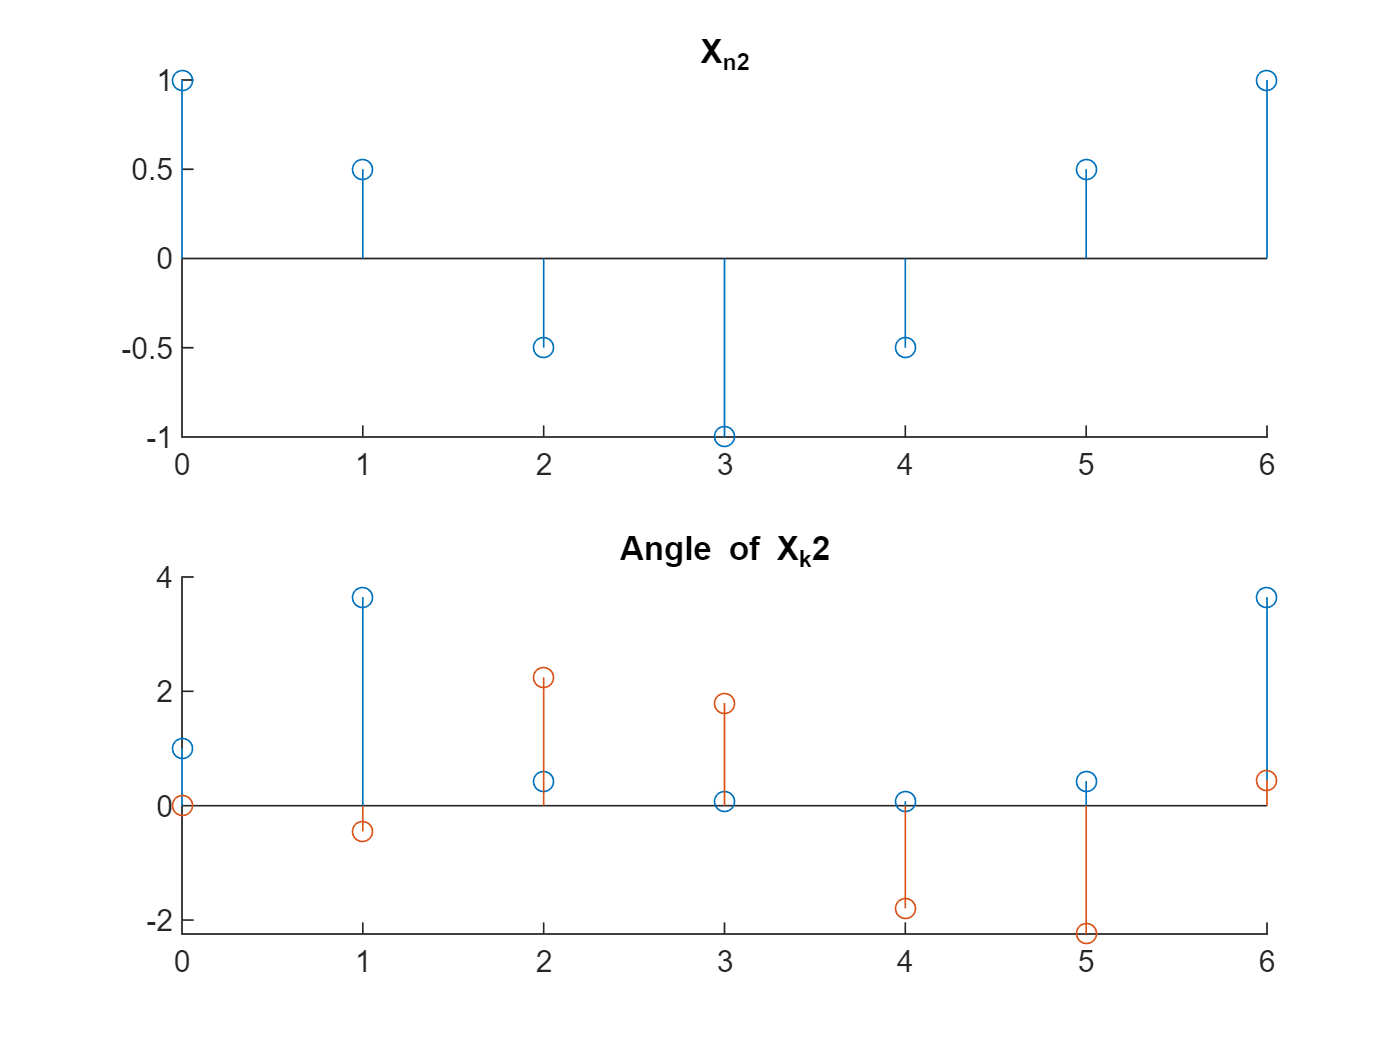

N=7;
n = 0:1:N-1;

x_n2 = transpose(cos((pi/3).*n));

x_k2 = myfft(x_n2);

figure(2)
subplot(2,1,1);
hold on
title('X_{n2}');
stem(n,x_n2);

subplot(2,1,2);
hold on
title('X_k2');
stem(n,abs(x_k2));
title('Angle of X_k2')
stem(n,angle(x_k2));

Task 5

Task 6

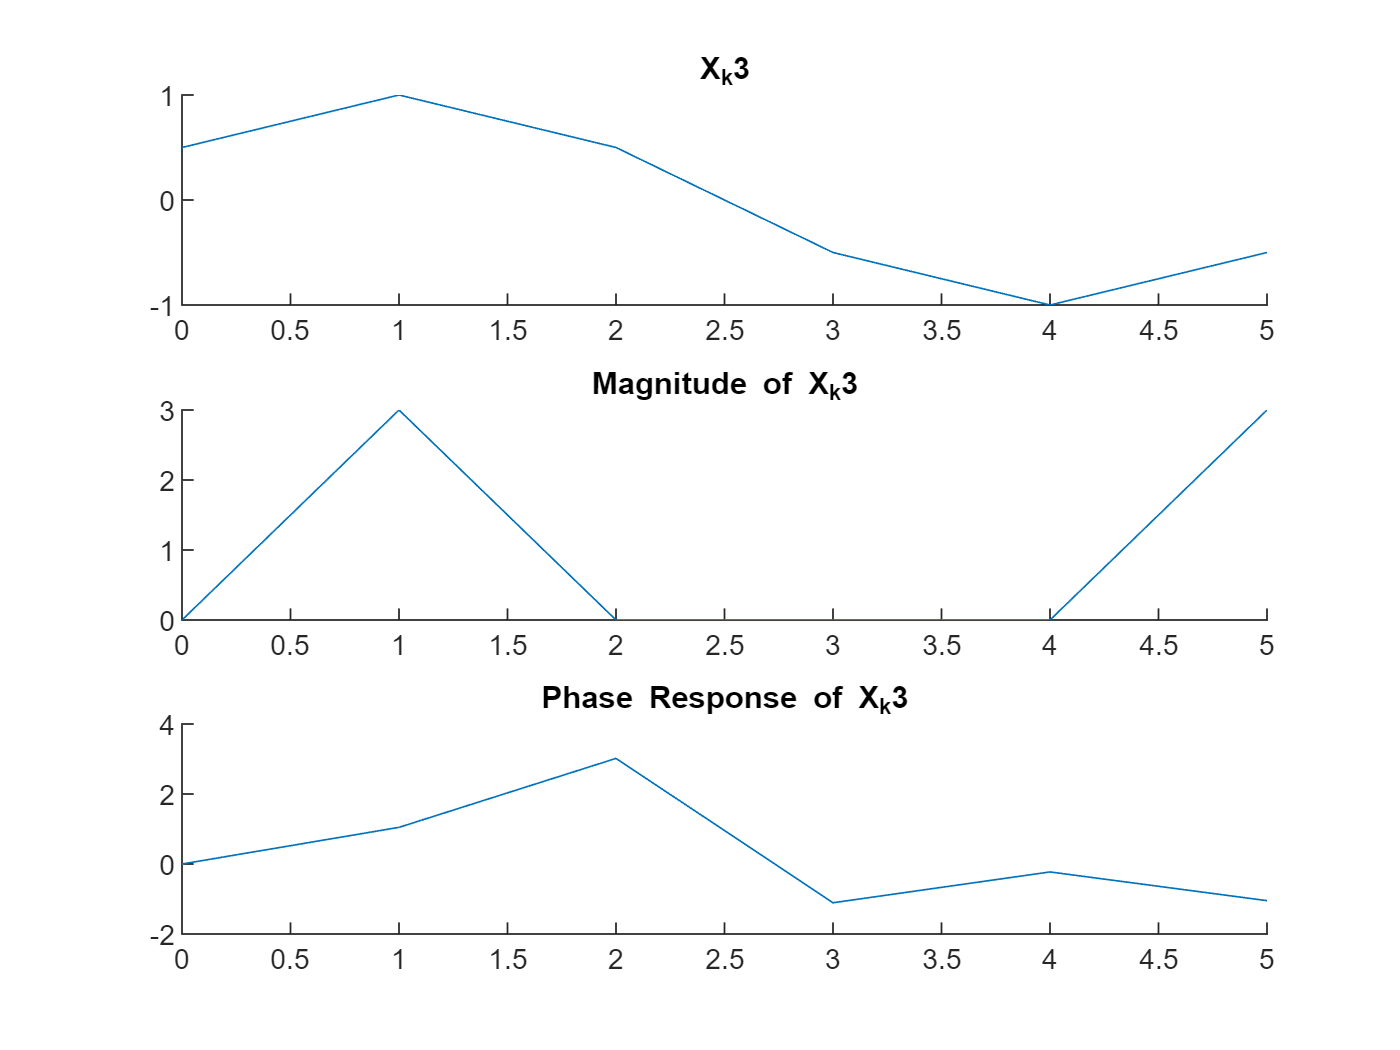

N=6; %Phase shifted
n = 0:1:N-1;

x_n3 = transpose(cos((pi/3).*(n-1)));

x_k3 = myfft(x_n3);

figure(3)
subplot(3,1,1);
hold on
title('X_k3');
plot(n,x_n3);
subplot(3,1,2);
hold on
title('Magnitude of X_k3')
plot(n,abs(x_k3));

subplot(3,1,3);
hold on
title('Phase Response of X_k3')
plot(n,angle(x_k3));

Task 8

Task 9

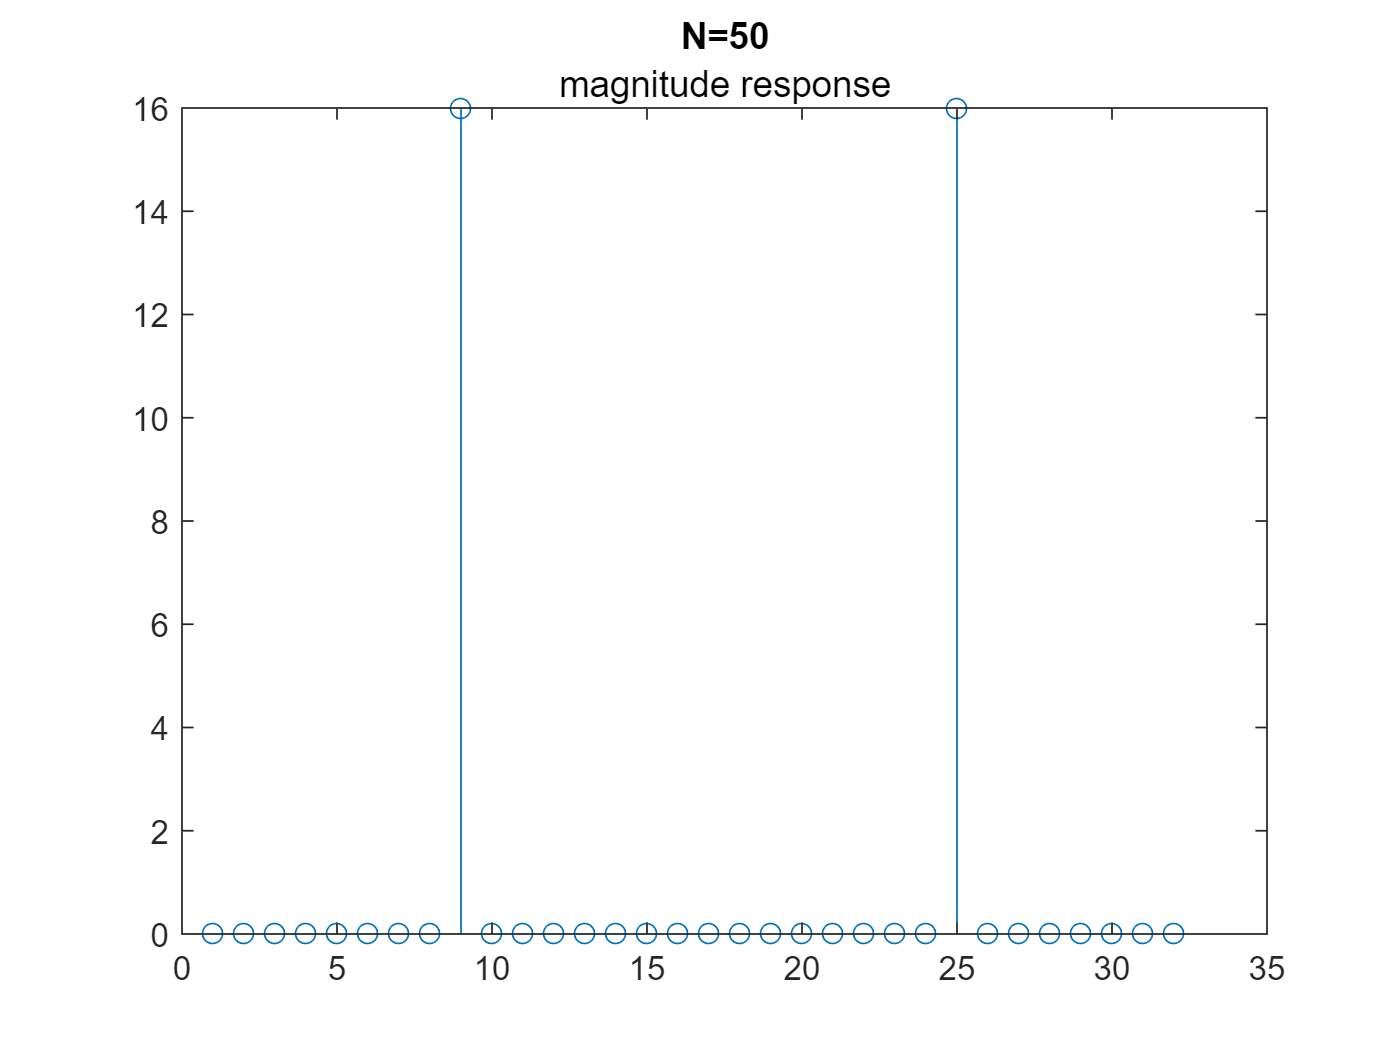

N=50;
n = 0:pi/2:N-1;
x_n4 = cos(n);
x_k4 = myfft(transpose(x_n4));
figure(5);
stem(abs(x_k4));
title("N=50", "magnitude response")
hold off

Part 3

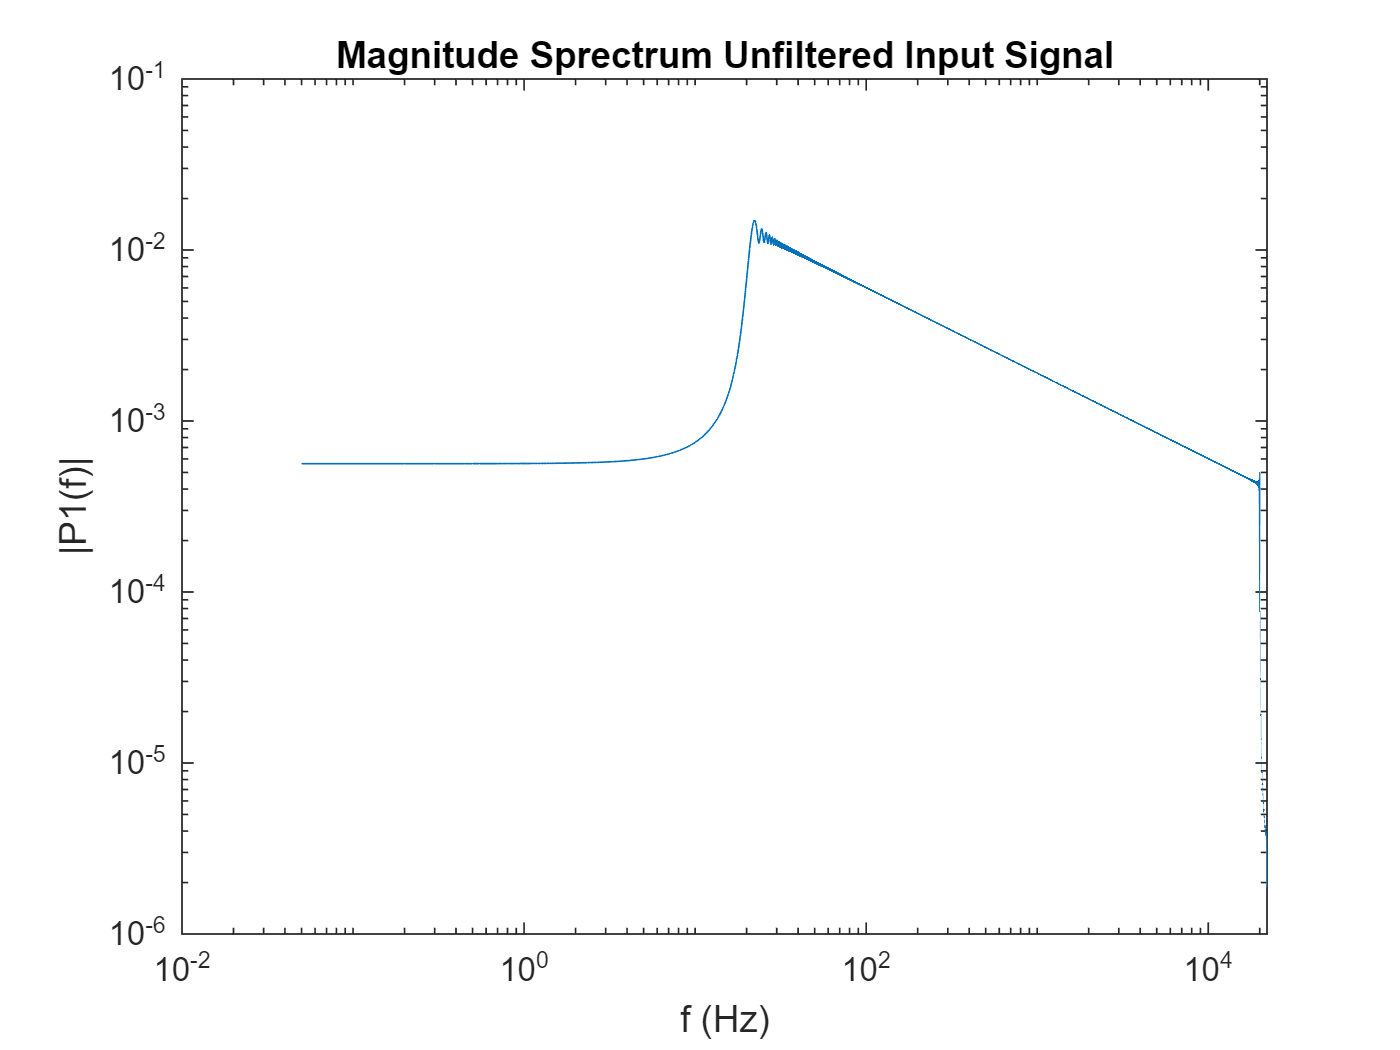

[x_log, fs_log] = audioread("audiocheck.net_sweep20-20klog.wav");
[x_lin, fs_lin] = audioread("audiocheck.net_sweep20-20klin.wav");
Fs = fs_log;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(x_log);             % Length of signal
t = (0:L-1)*T;        % Time vector
Y = fft(x_log);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
loglog(f,P1) 
title("Magnitude Sprectrum Unfiltered Input Signal")
xlabel("f (Hz)")
ylabel("|P1(f)|")

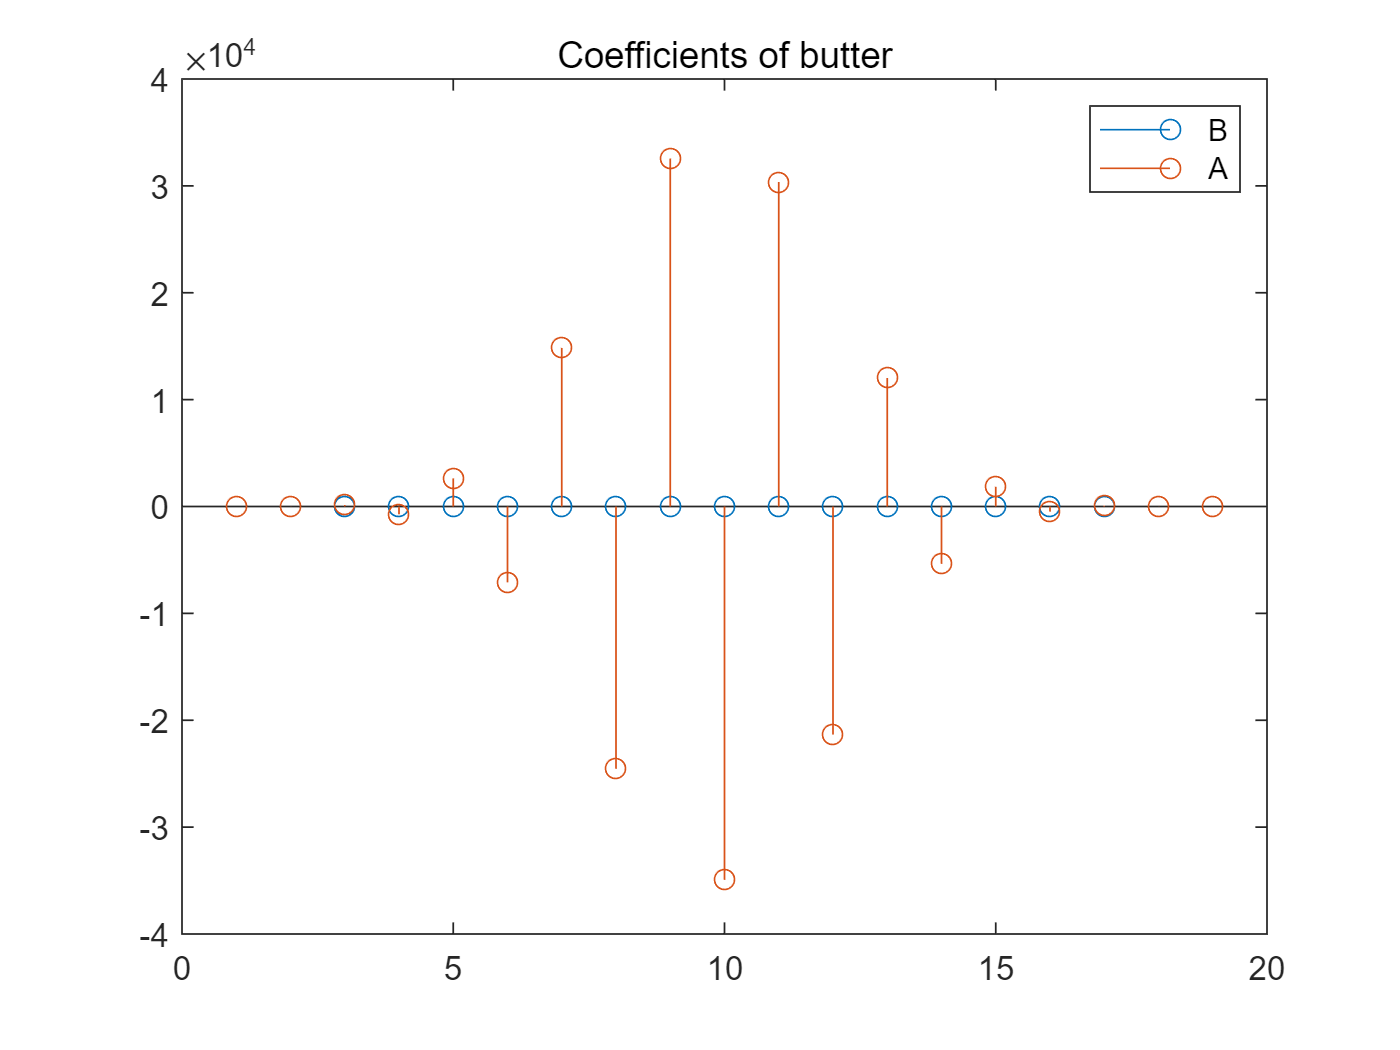

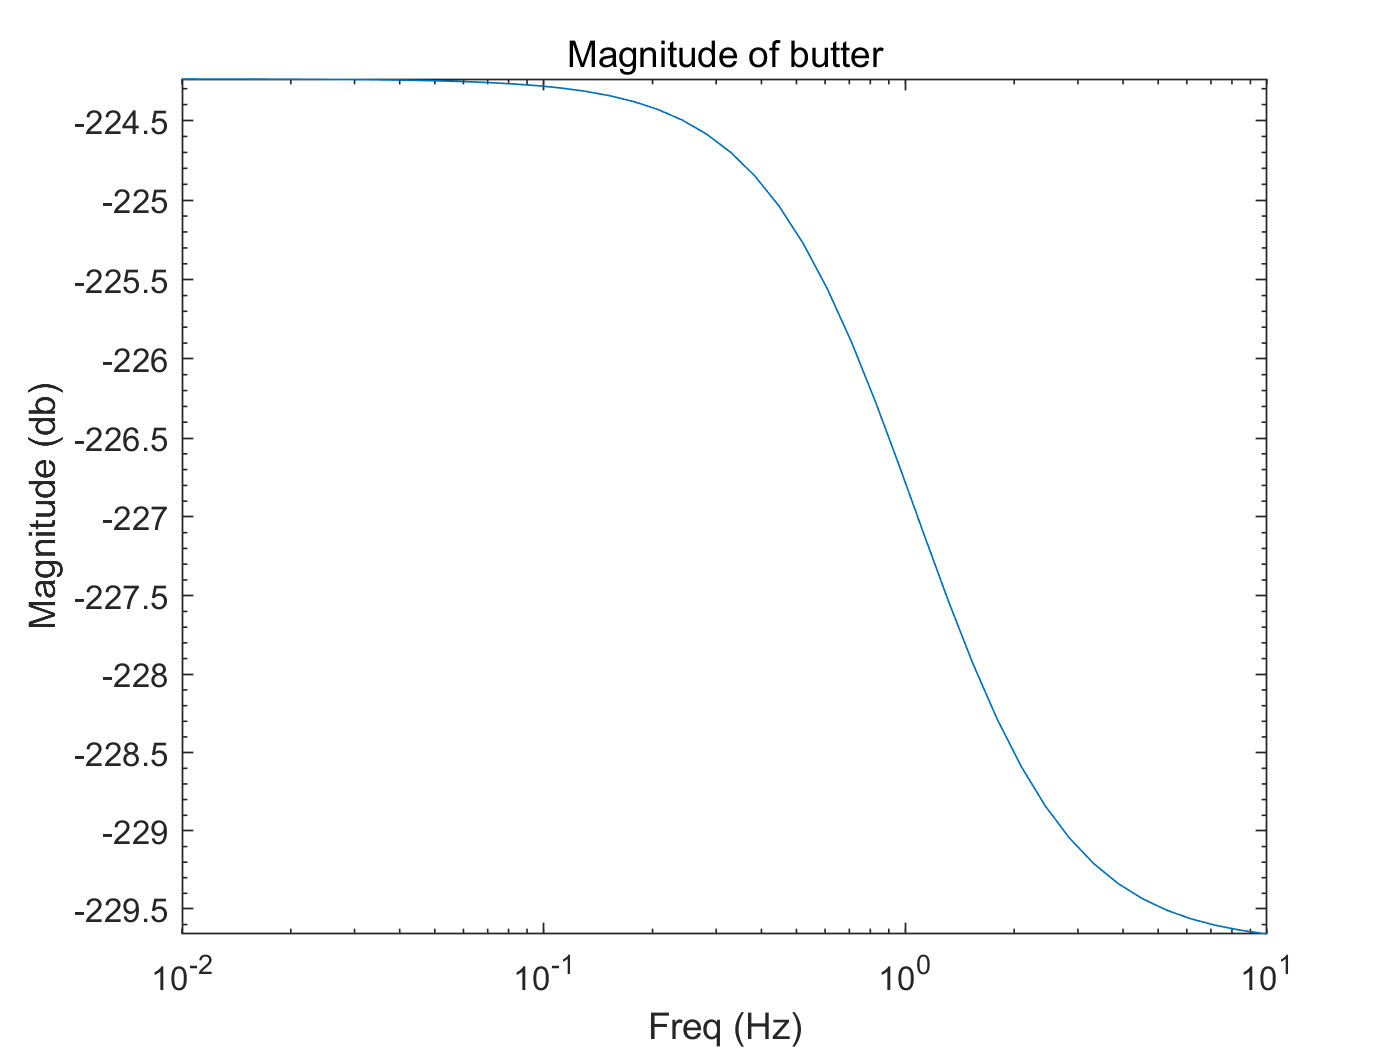

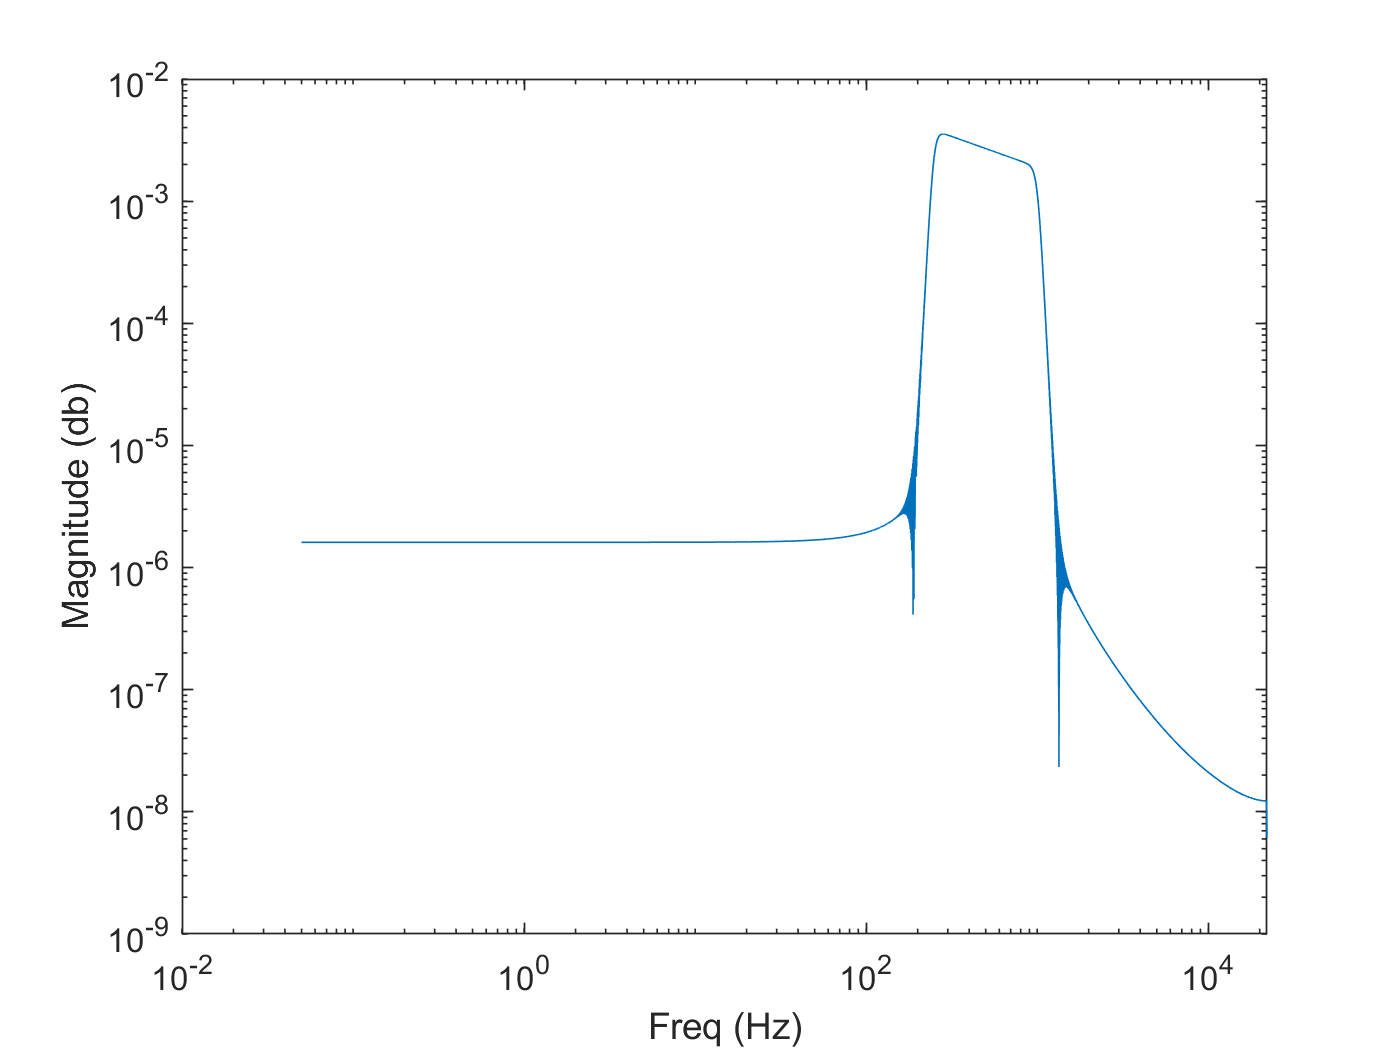

iir(SOS_butter, G_butter,"butter") %butterworth

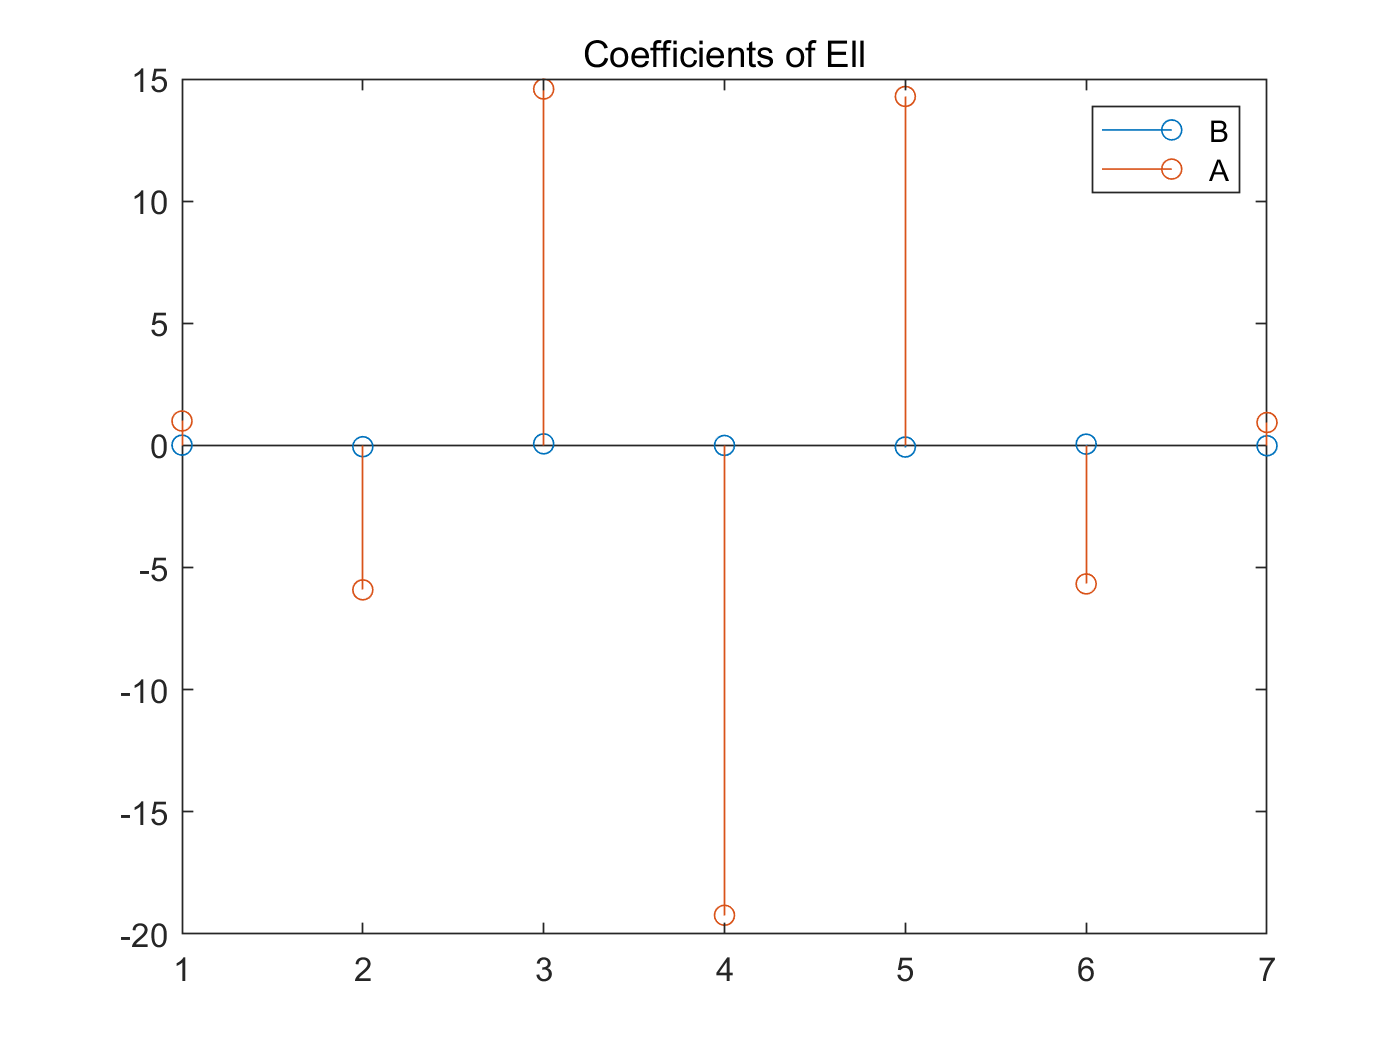

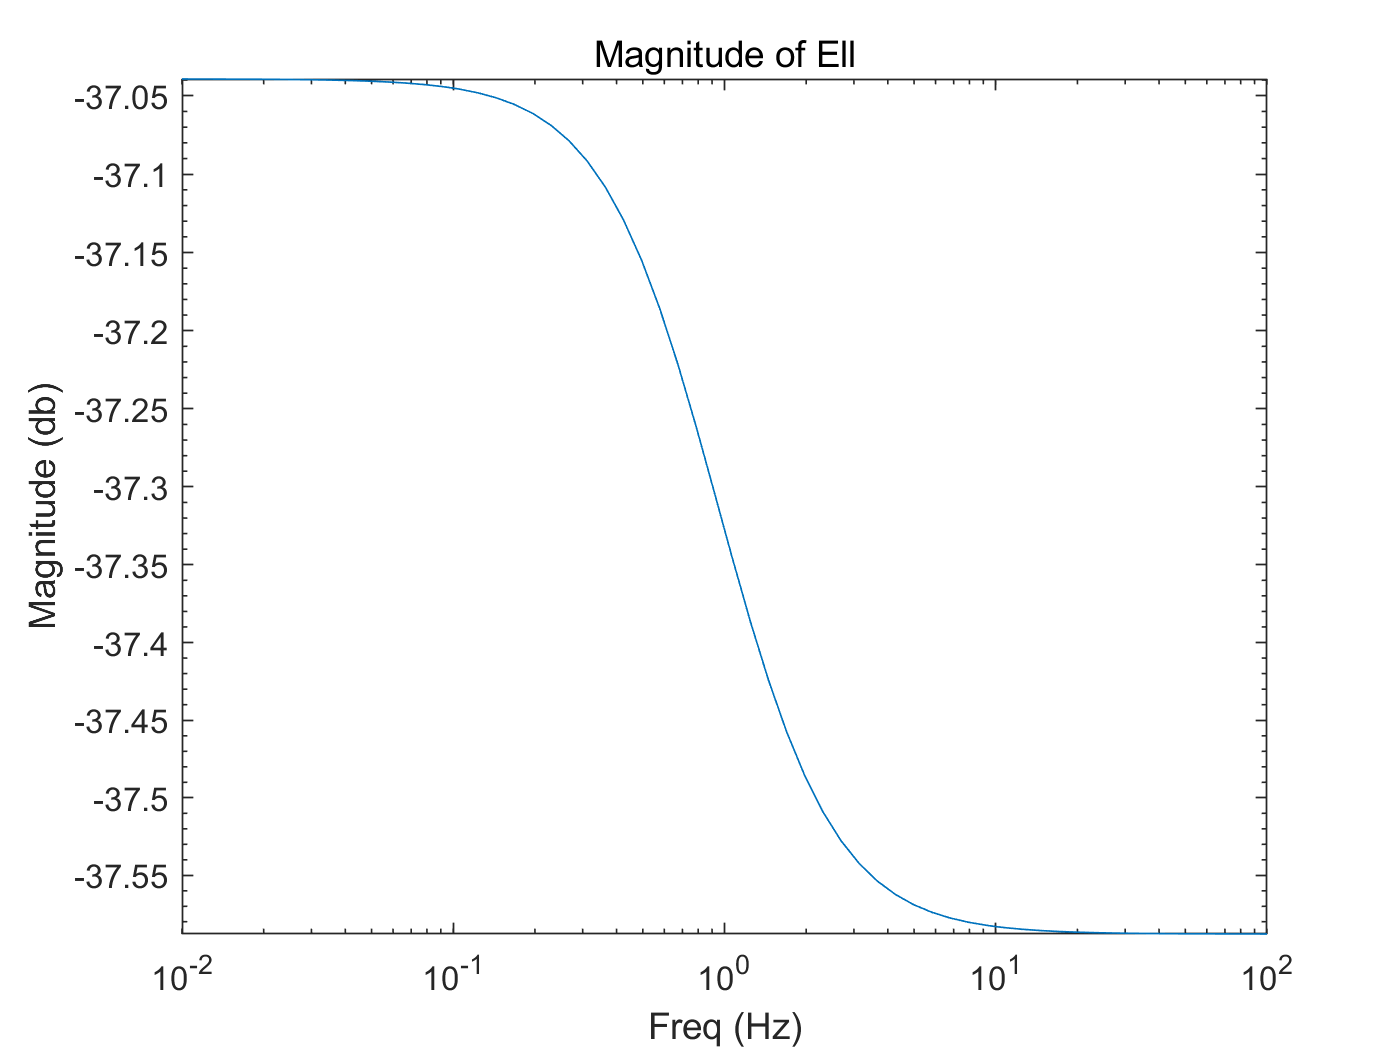

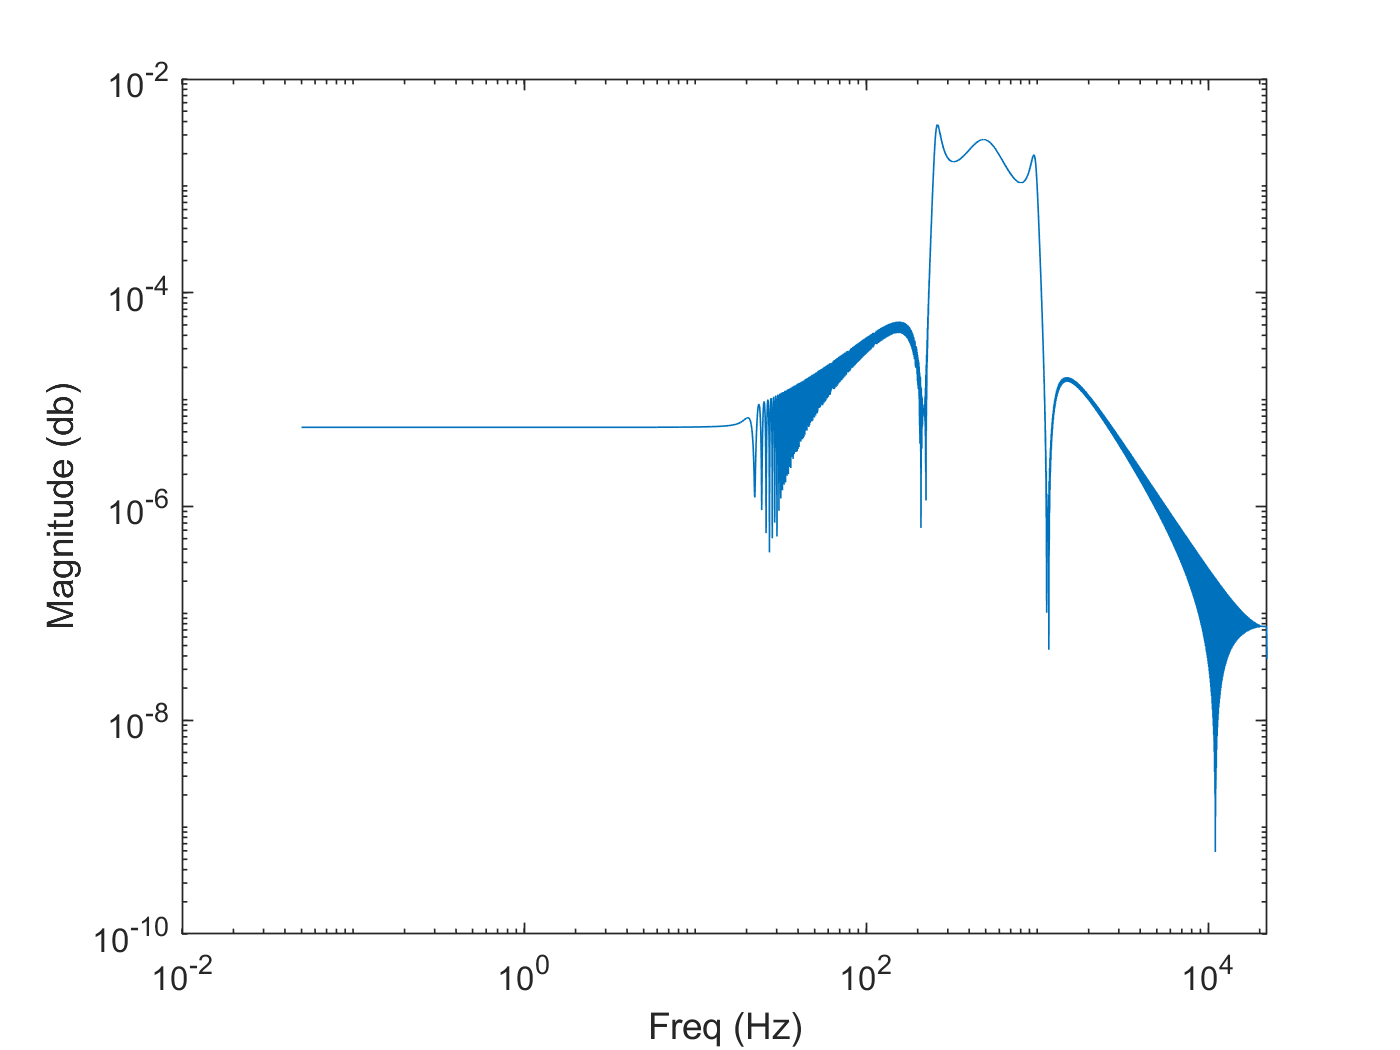

iir(SOS_Ell,G_Ell,"Ell");

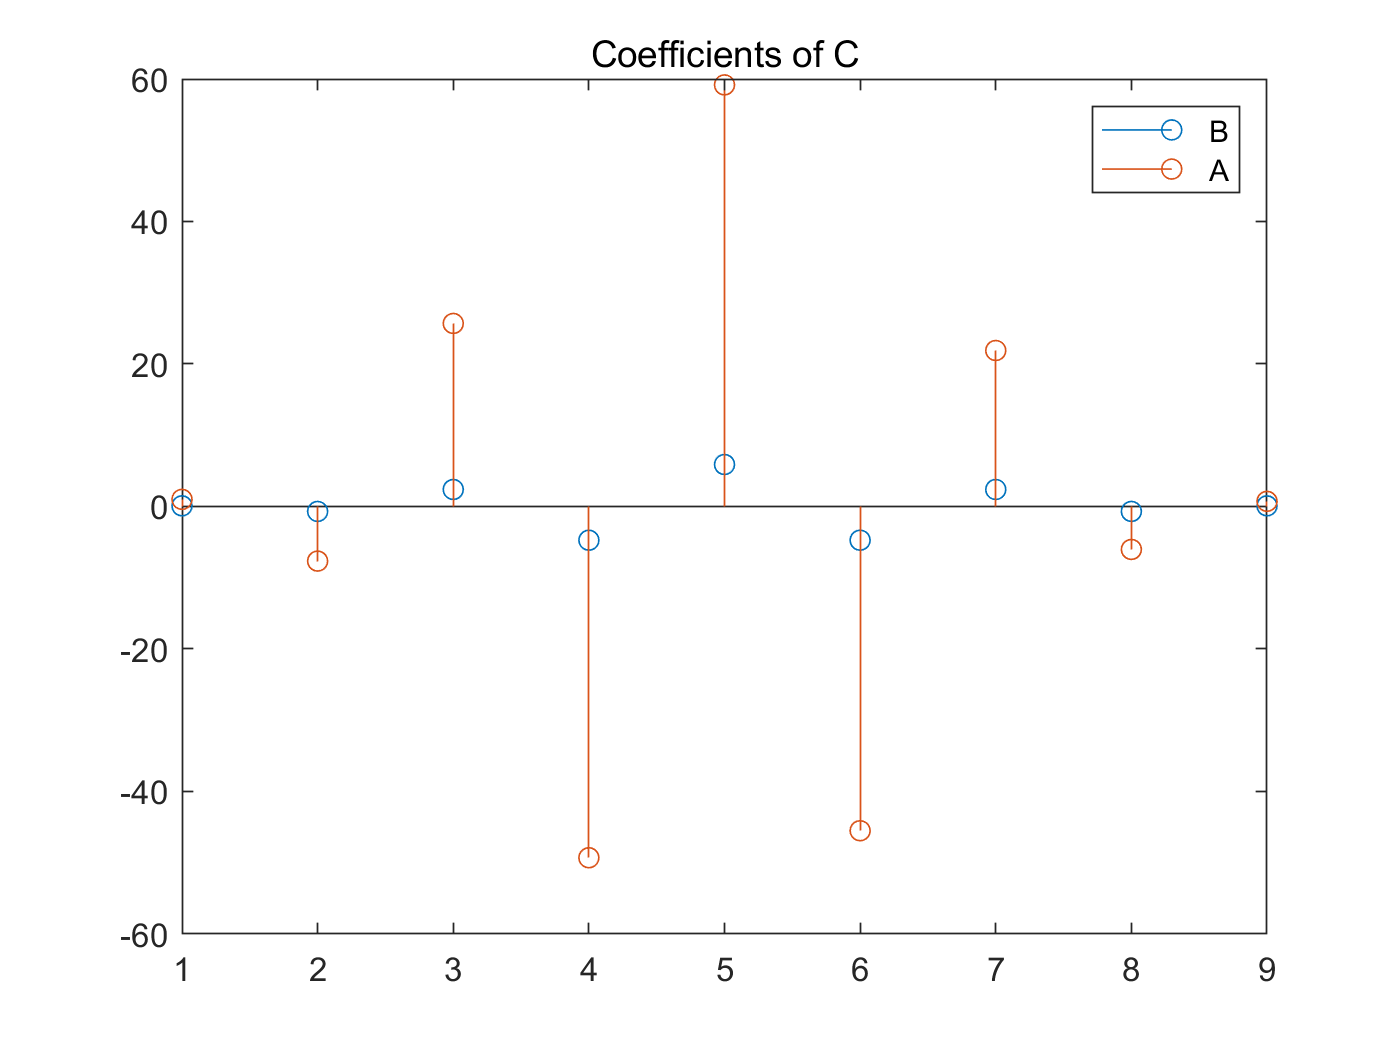

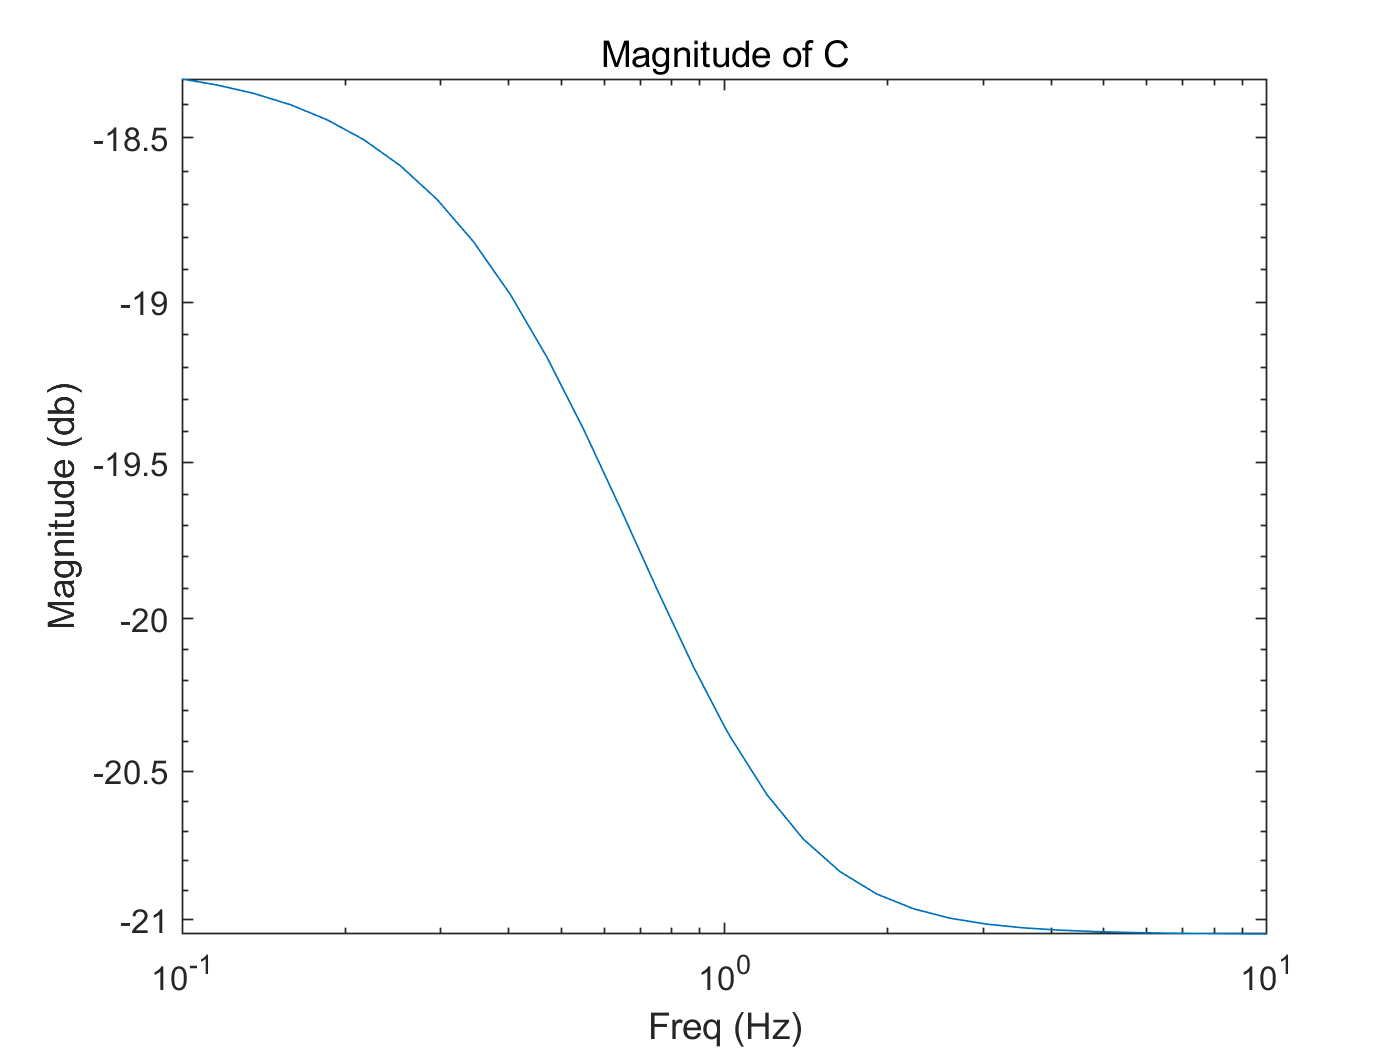

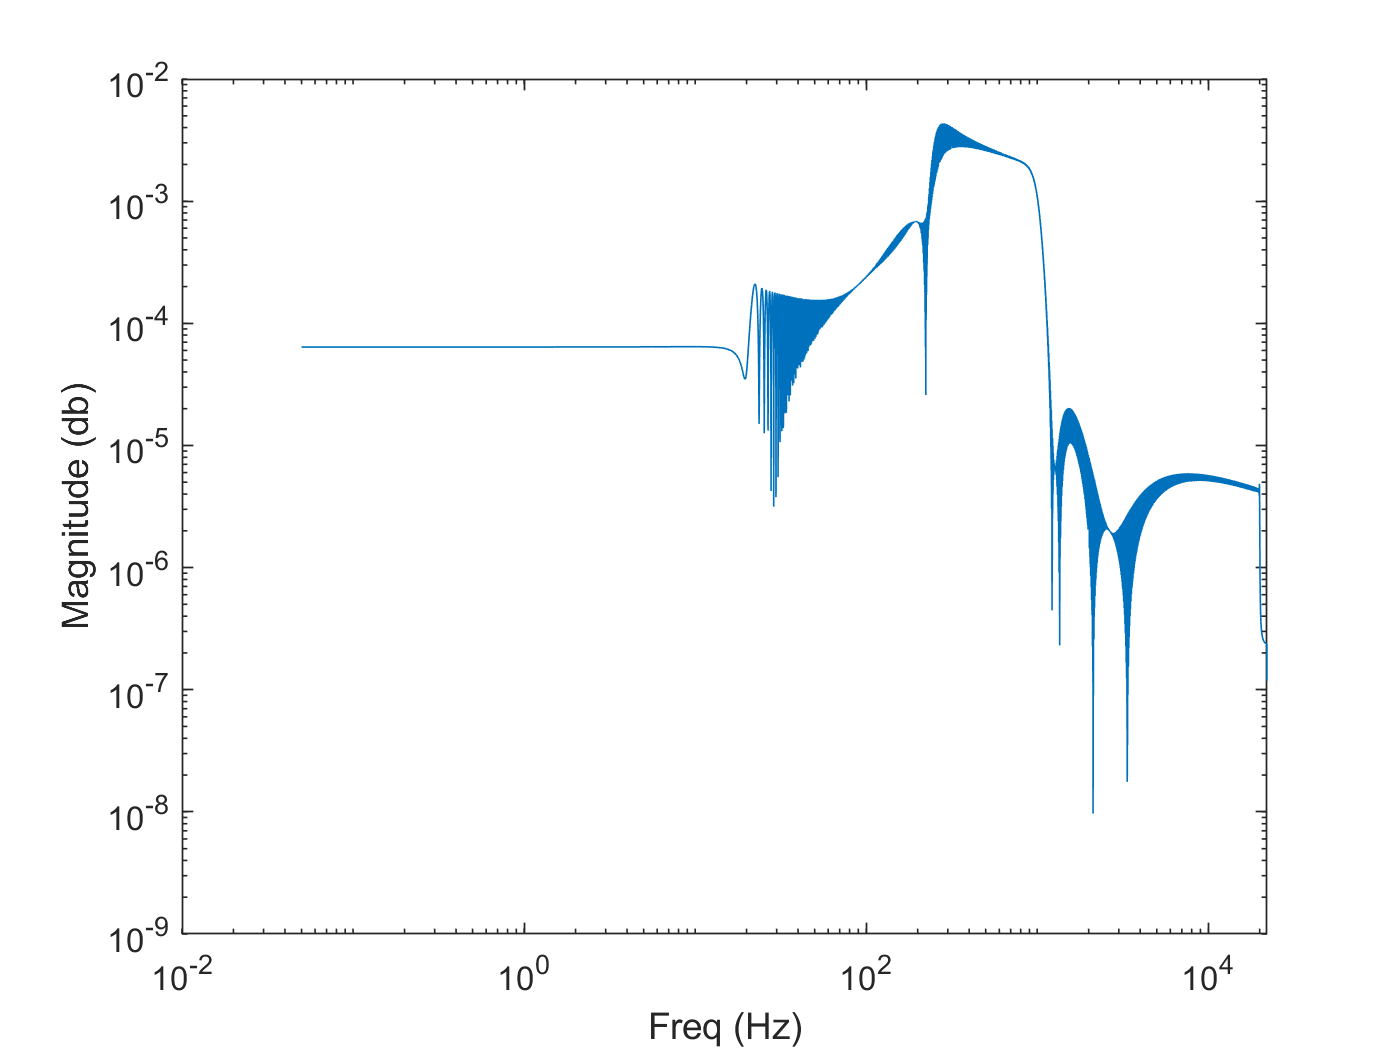

iir(SOS_C,G_C,"C")

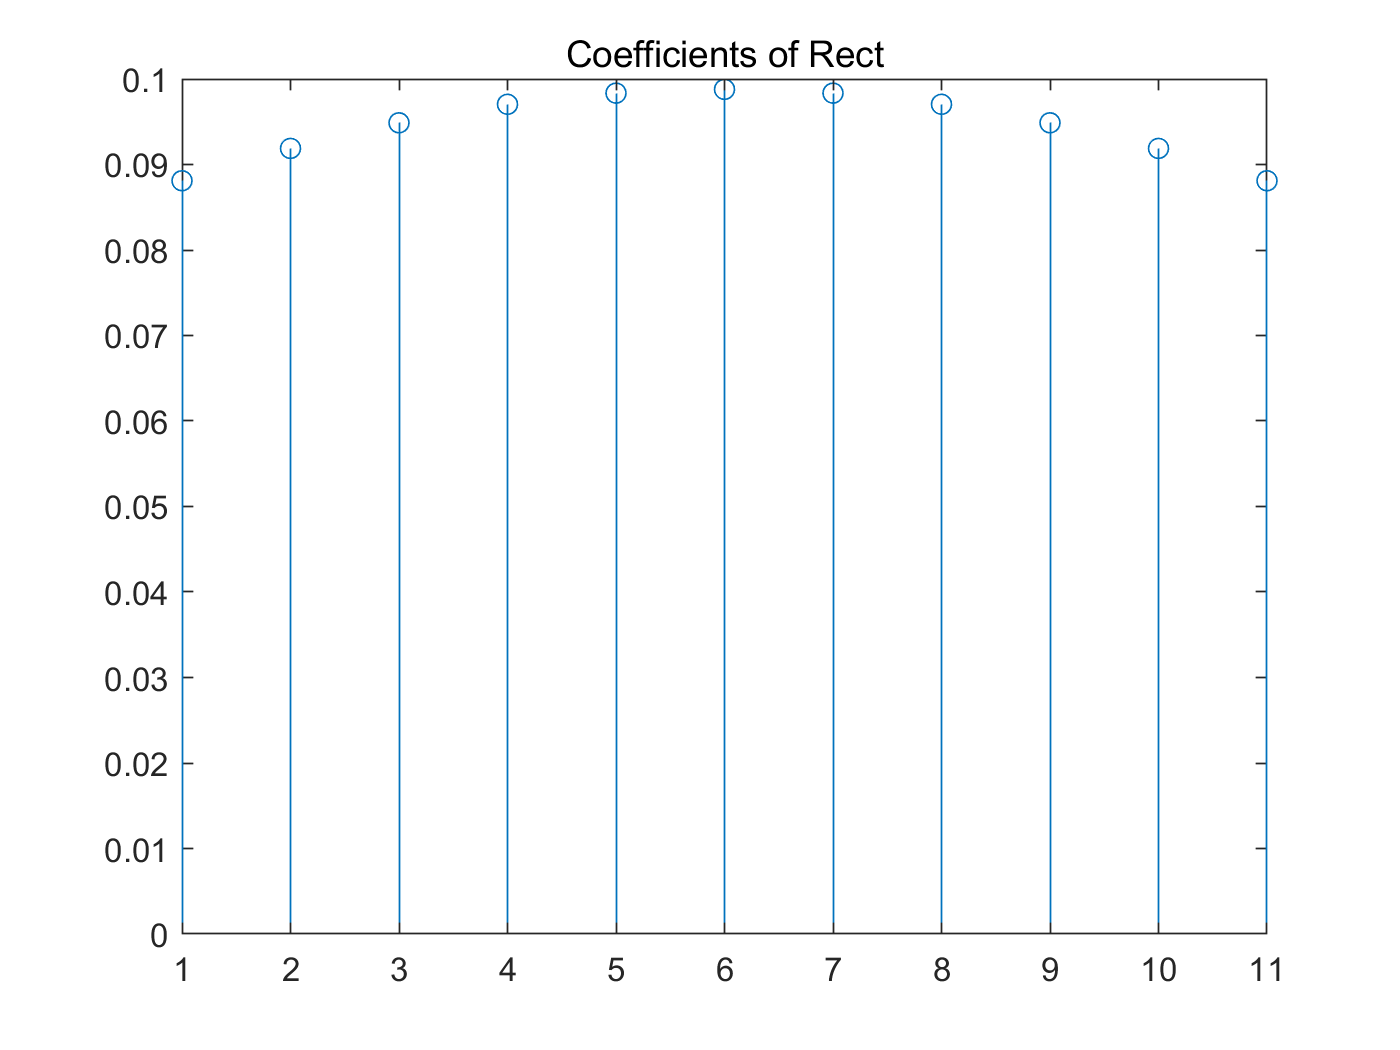

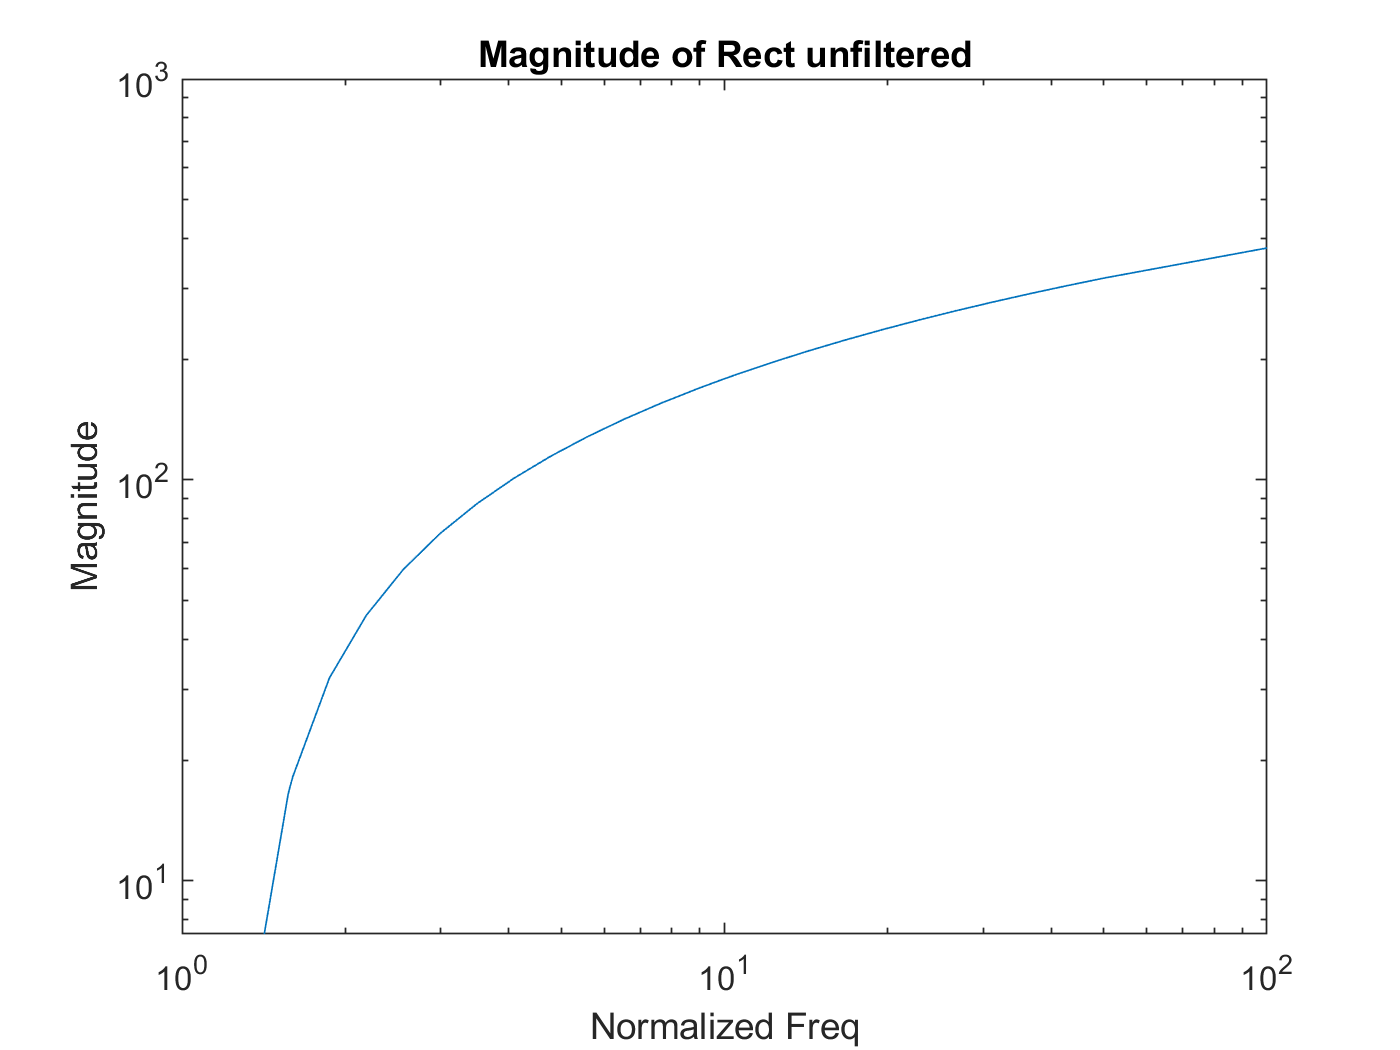

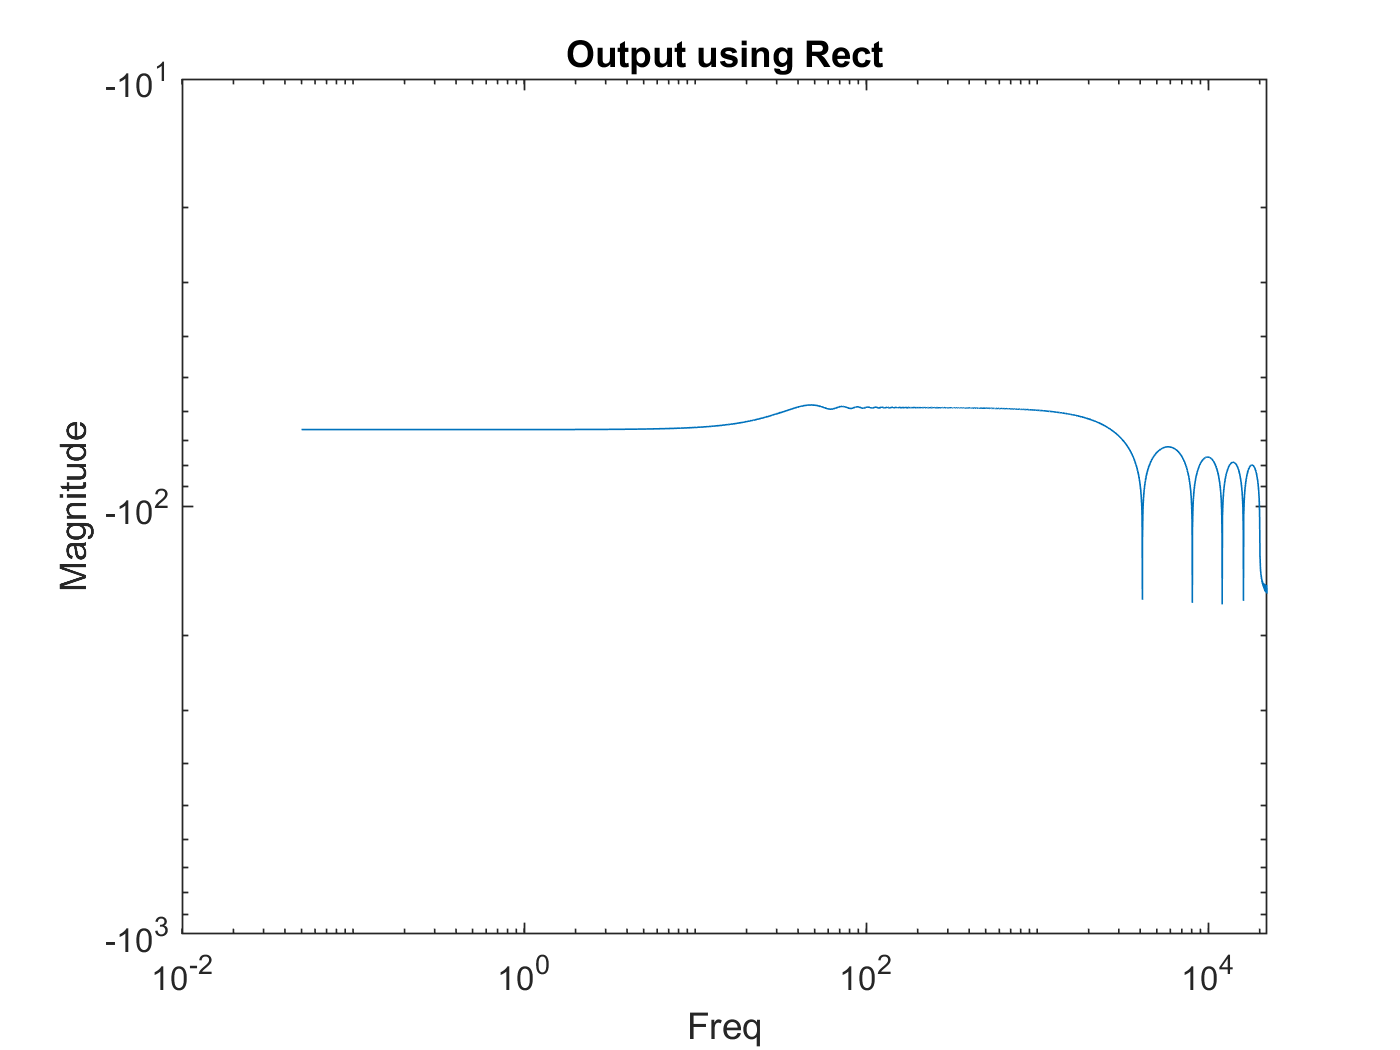

ans = 1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002


fir(B_Rect,"Rect")

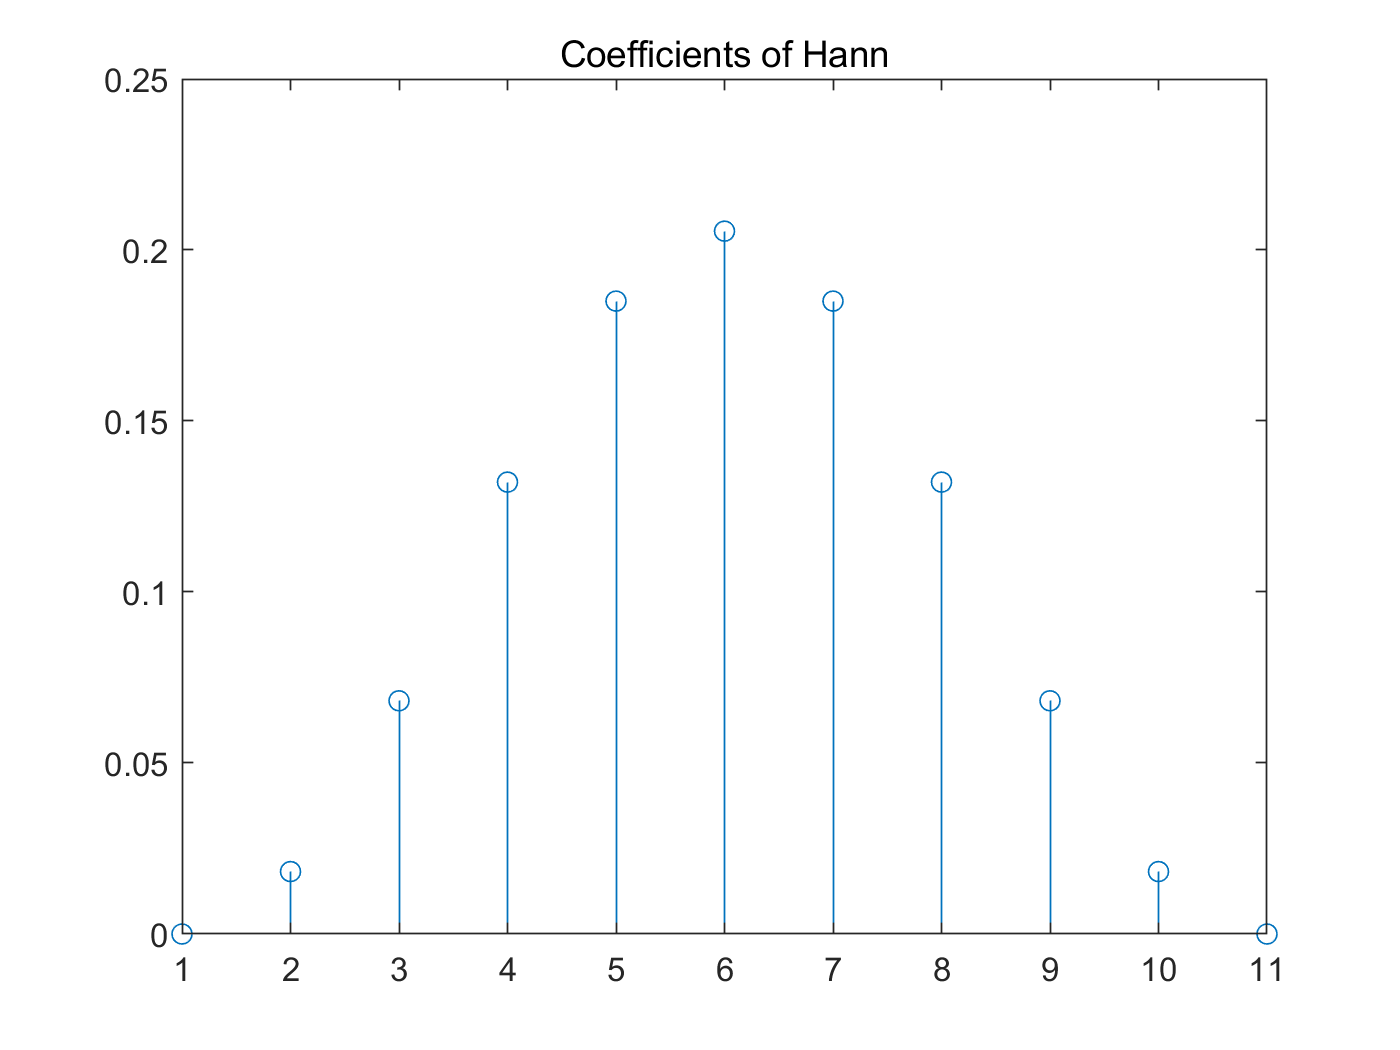

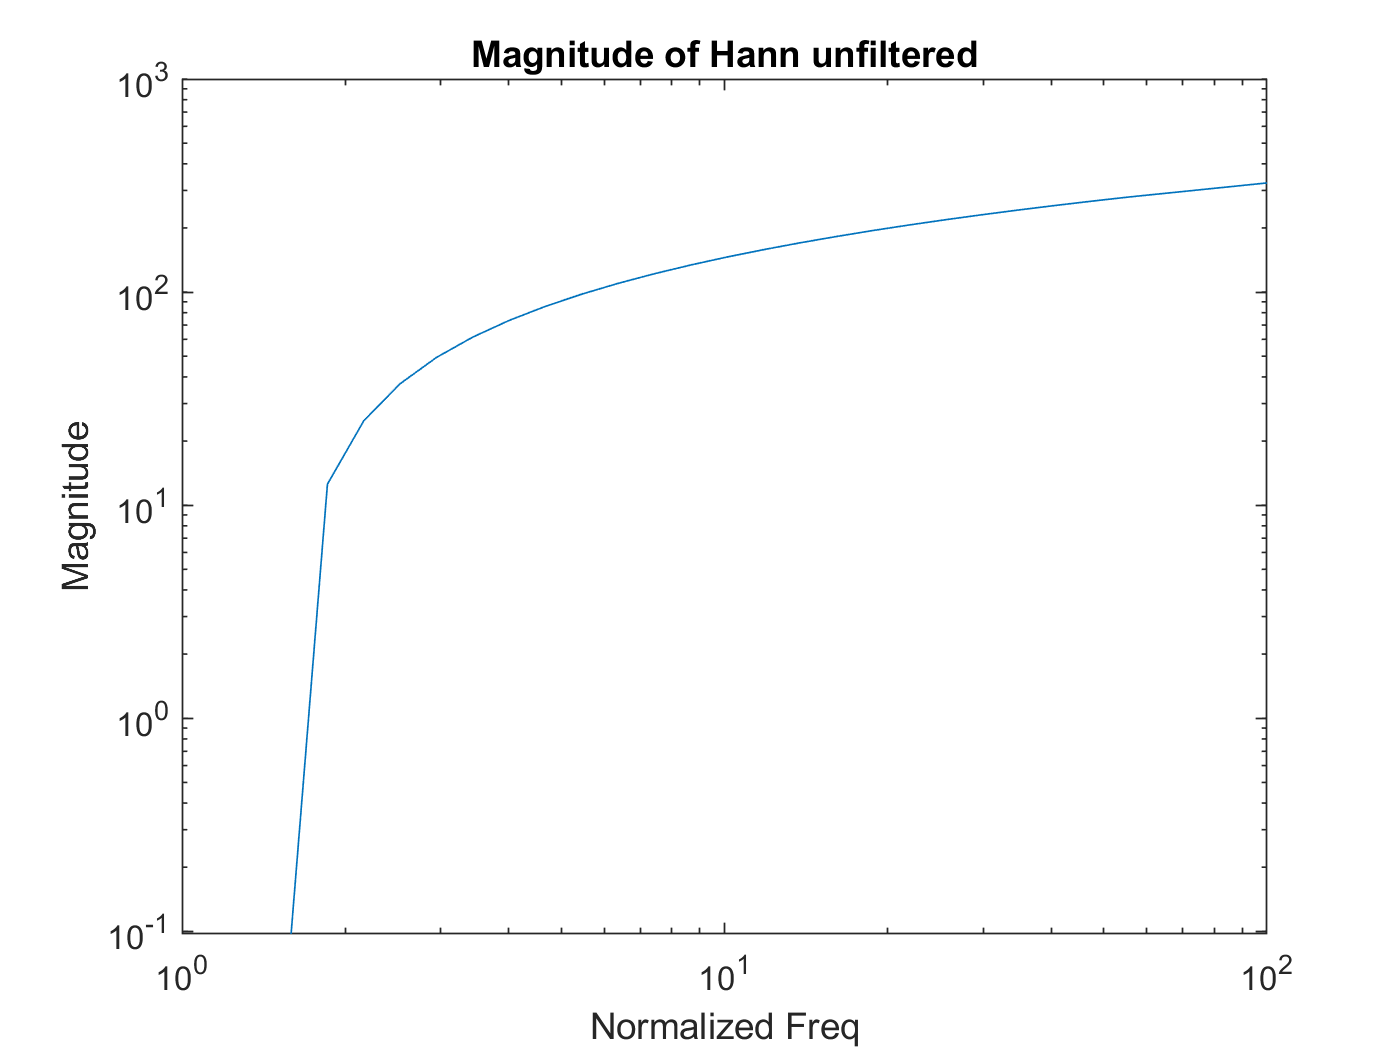

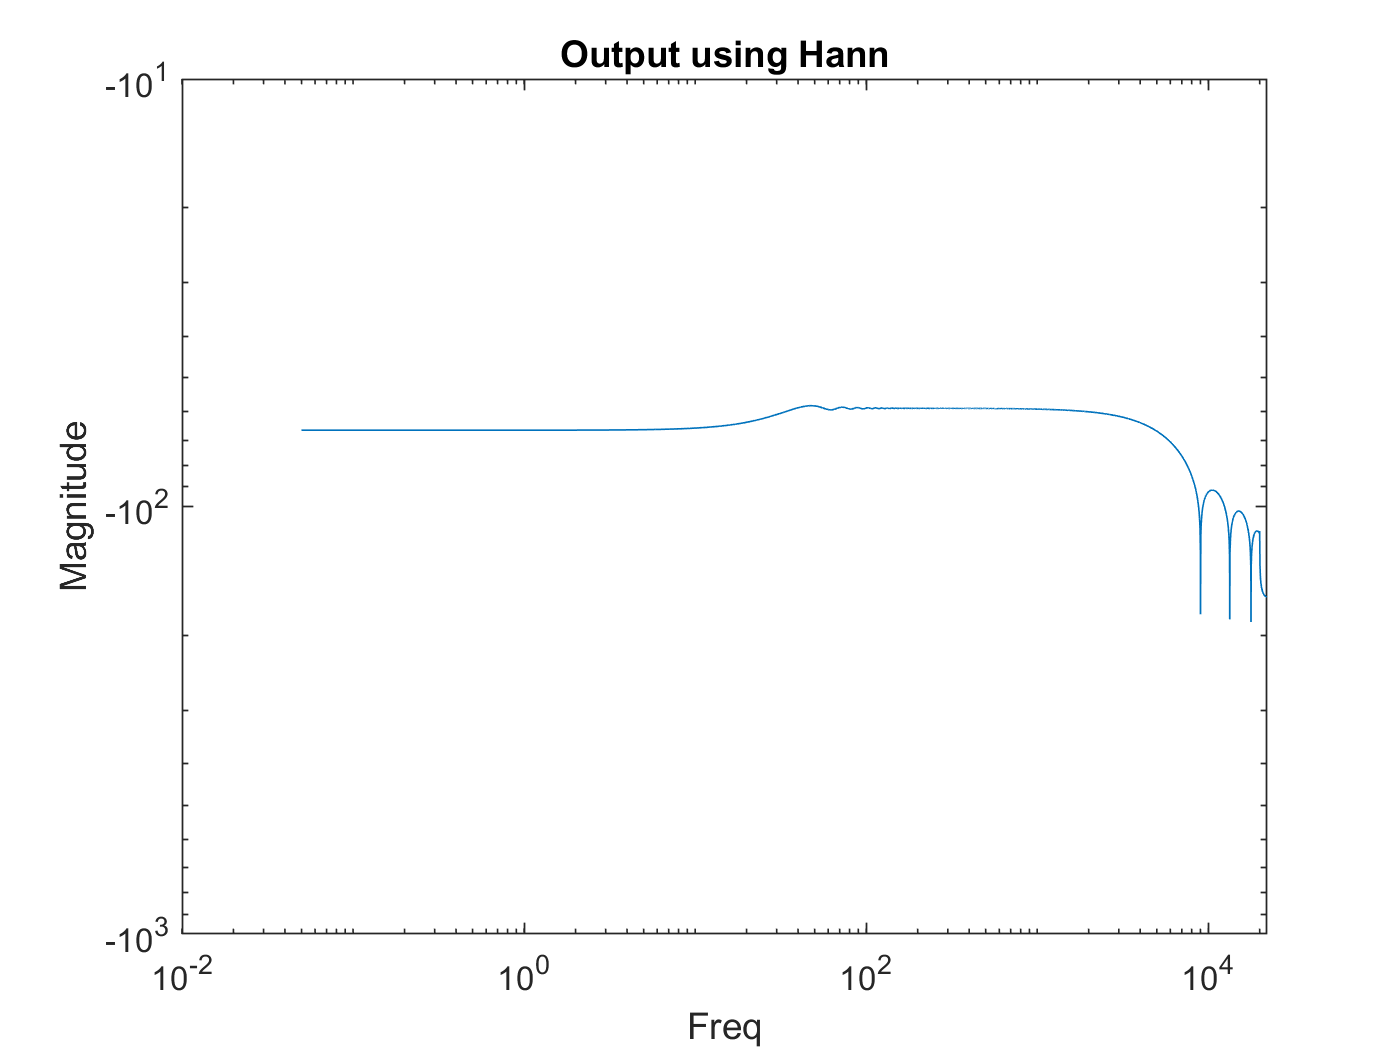

ans = 1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002


fir(B_Hann,"Hann")

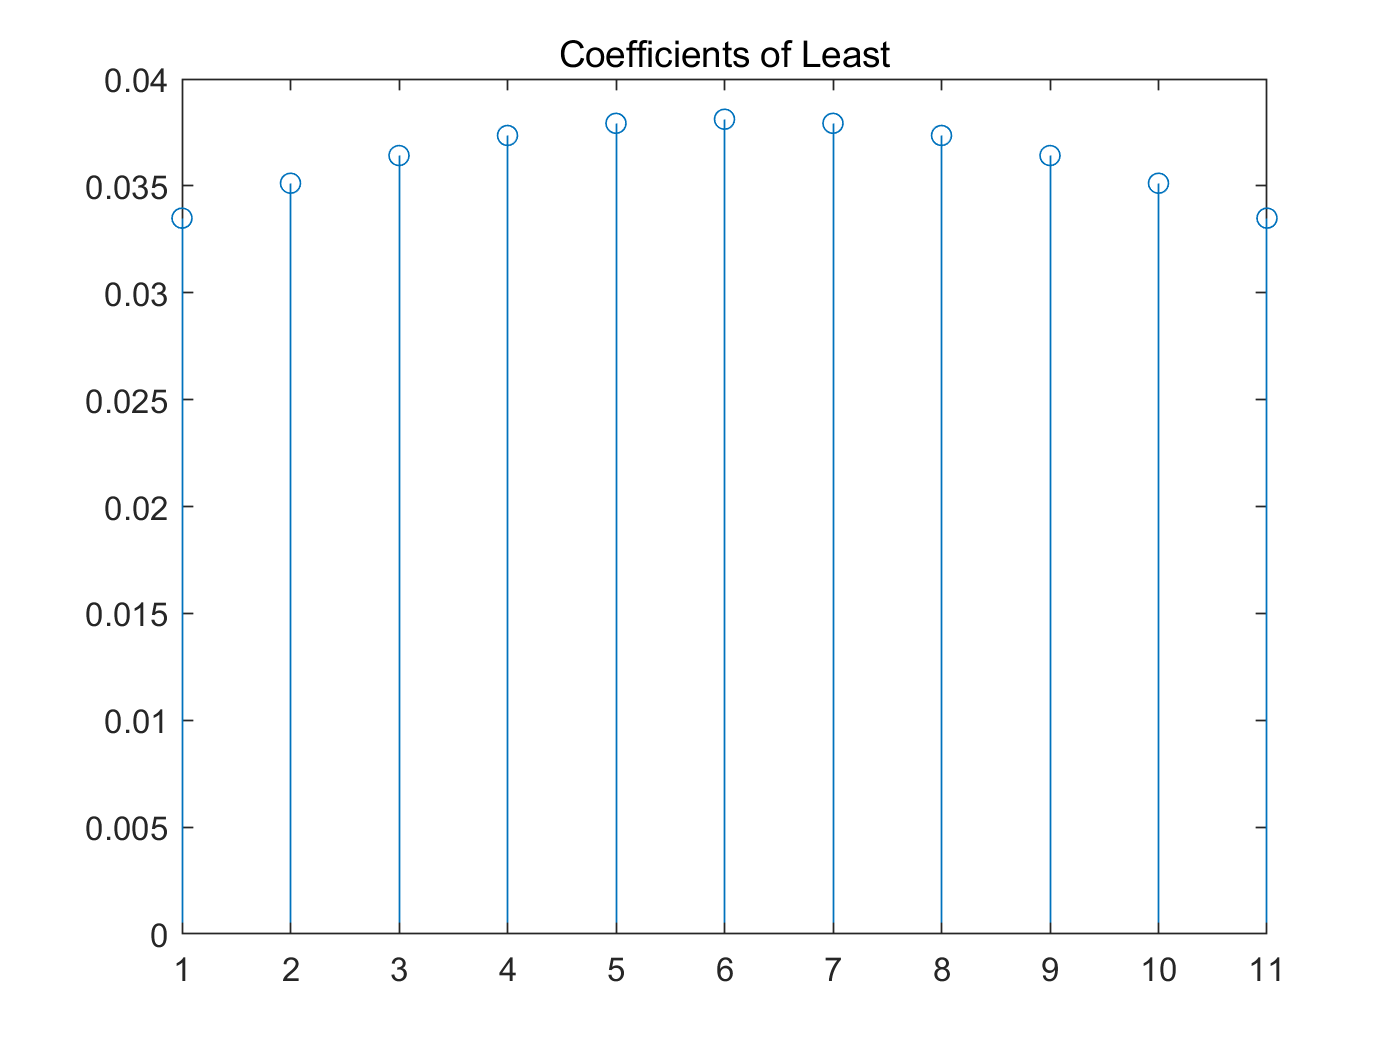

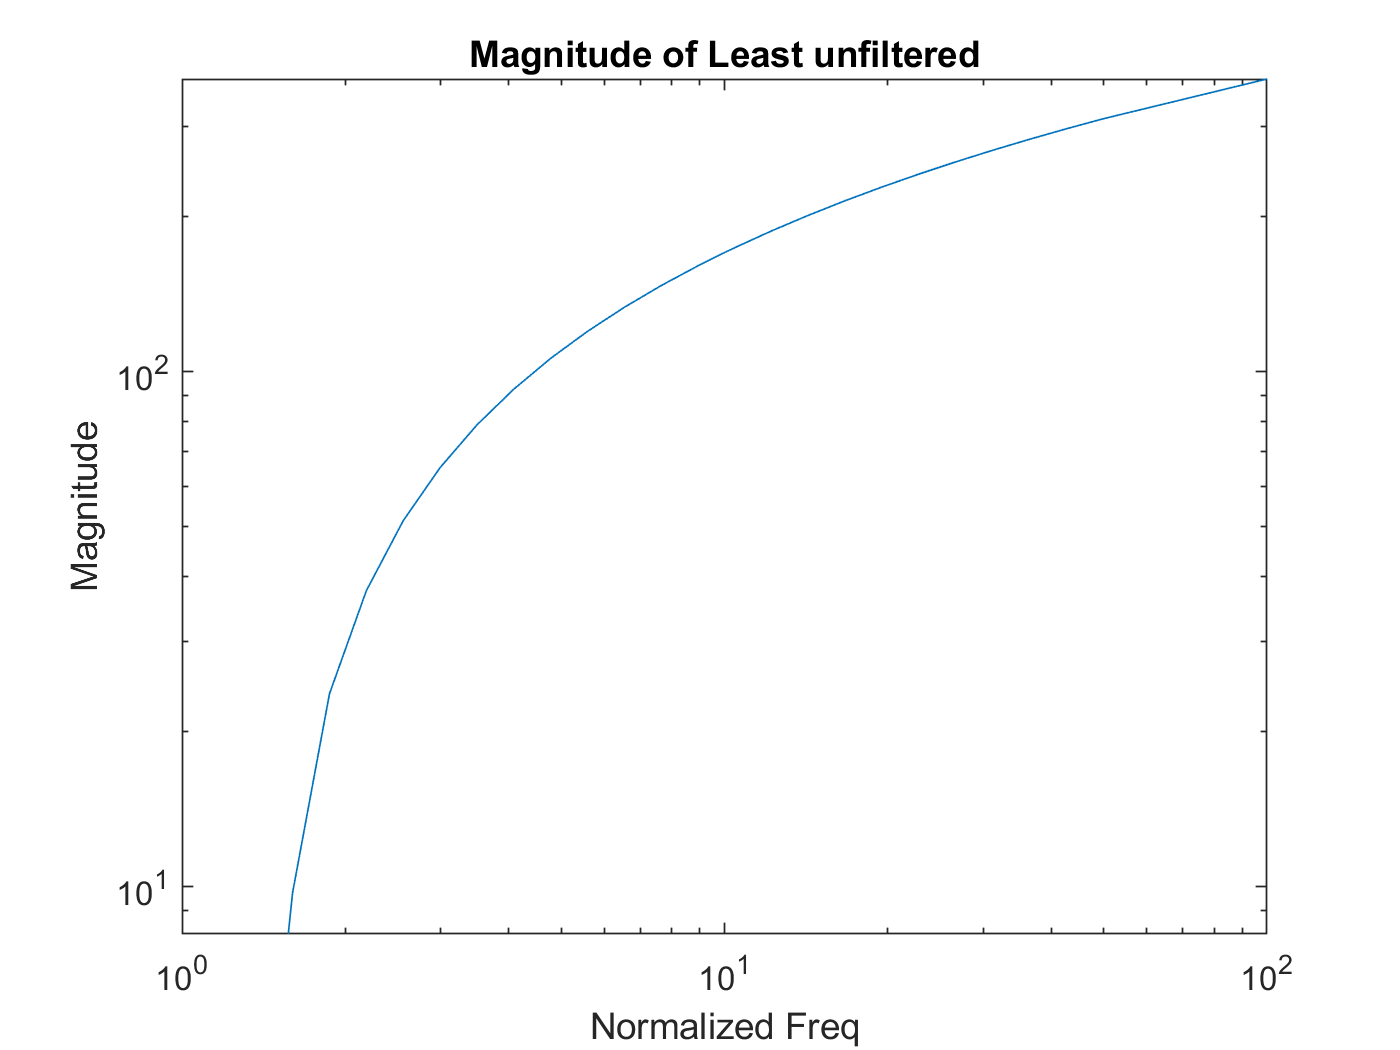

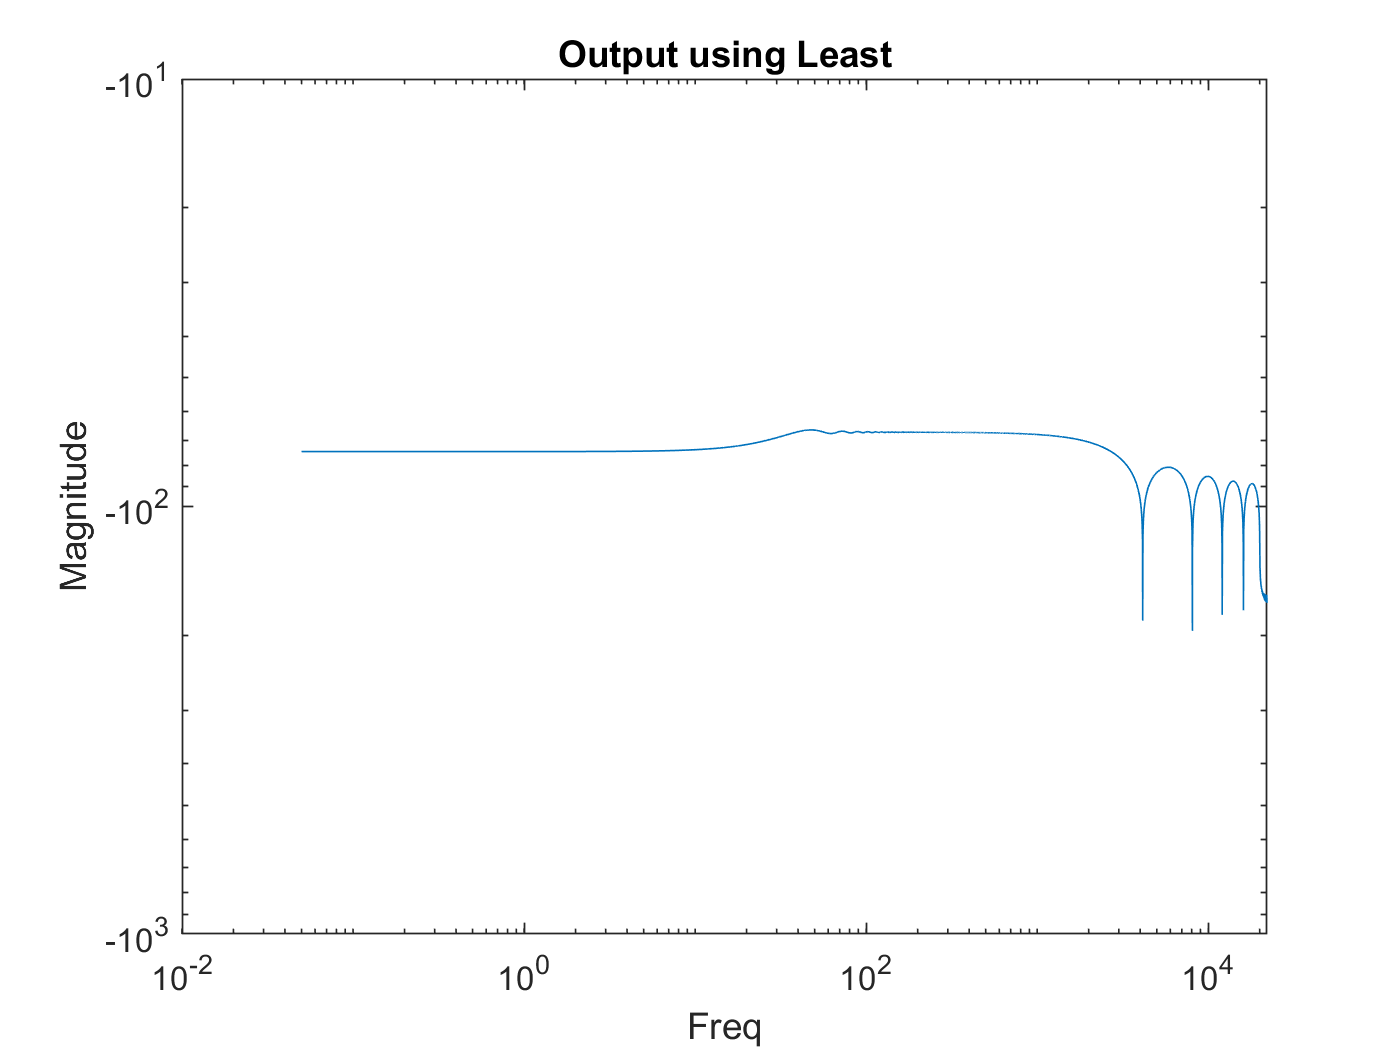

ans = 1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002


fir(Least,"Least")

Butterworth

Hann

Least

Ell

Cheyv

Rectangle

Filters = {'Butterworth'; ' Chebychev Type II'; 'Elliptical'; 'Rectangle'; 'Hann'; 'Least Squarred'};
StopBandRipple = [0; 0; 0; 0; 0; 0];
PassBandRipple = [0; 0; 0; 0; 0; 0];
TransmitionBandwidth = [0; 0; 0; 0; 0; 0];
PassBandGain = [0; 0; 0; 0; 0; 0];
StopBandGain = [0; 0; 0; 0; 0; 0];
NumberCoeff =[0; 0; 0; 0; 0; 0];
T = table(Filters, StopBandRipple,PassBandRipple,TransmitionBandwidth, PassBandGain,StopBandGain,NumberCoeff)

T = 6×7 table
           Filters            StopBandRipple    PassBandRipple    TransmitionBandwidth    PassBandGain    StopBandGain    NumberCoeff
    ______________________    ______________    ______________    ____________________    ____________    ____________    ___________

    {'Butterworth'       }          0                 0                    0                   0               0               0     
    {' Chebychev Type II'}          0                 0                    0                   0               0               0     
    {'Elliptical'        }          0                 0                    0                   0               0               0     
    {'Rectangle'         }          0                 0                    0 

function i = iir(x,y,audio)
[x_log, fs_log] = audioread("audiocheck.net_sweep20-20klog.wav");

[B, A] = sos2tf(x, y);
figure()
stem(B)
hold on
stem(A)
subtitle("Coefficients of " + audio)
legend('B','A')
figure()
hz = tf(B,A);
[mag,phase,omega] = bode(hz);
bode_plot = squeeze(mag2db(mag));
loglog(omega,bode_plot);
ylabel('Magnitude (db)');
xlabel('Freq (Hz)');
subtitle('Magnitude of ' + audio);
figure();
z = filtfilt(x,y,x_log);
Y = fft(z');
L = length(Y);
f = fs_log*(0:(L/2))/L;
P2 = abs(Y/L);
P1 = P2(1:(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
loglog(f, P1)
ylabel('Magnitude (db)');
xlabel('Freq (Hz)');

audiowrite(audio + '.wav',y,fs_log);
end

function f = fir(x,audio)
[x_lin, fs_lin] = audioread("audiocheck.net_sweep20-20klin.wav");

figure();
stem(x);
subtitle('Coefficients of ' + audio);

figure();
hz = tf(x,1);
[mag, phase, omega] = bode(hz);
bode_plot = squeeze(mag2db(mag));
loglog(omega,bode_plot);
title('Magnitude of ' + audio + " unfiltered");
ylabel('Magnitude');
xlabel('Normalized Freq');

figure();
y=filter(x,1,x_lin);
Y = fft(y');
L = length(x_lin);
f = fs_lin*(0:(L/2))/L;
P2 = abs(Y/L);
P1 = P2(1:(L/2)+1);
P1(2:end) = 2*P1(2:end);
bode_plot=mag2db(P1);
loglog(f,bode_plot);

title('Output using ' + audio);
ylabel('Magnitude');
xlabel('Freq');

audiowrite(audio + '.wav',y,fs_lin);
end

function x = xaxis()
L = length(x_log);
Y = fft(x_log);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);

f = fslog*(0:(L/2))/L;

bode_plot = P1;

loglog(f, bode_plot);

end
